# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(kristen_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

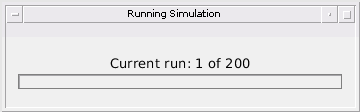

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
%    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =   100.8869       NaN       NaN       NaN       NaN
  100.6060       NaN       NaN       NaN       NaN
  100.5699       NaN       NaN       NaN       NaN
  100.2557       NaN       NaN       NaN       NaN
   99.9742       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =   101.0000  100.7333  100.4666  100.2000   99.9333   99.6666   99.3999   99.1333   98.8666   98.5999


estimated_velocities =     8.0001       NaN       NaN       NaN       NaN
    7.9868       NaN       NaN       NaN       NaN
    8.0220       NaN       NaN       NaN       NaN
    7.9900       NaN       NaN       NaN       NaN
    8.0110       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =      8     8     8     8     8     8     8     8     8     8


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.1131
    0.1273
    0.1032
    0.0557
    0.0409
         0
         0
         0
         0
         0


percent_error_velocities =     0.0001
    0.0132
    0.0220
    0.0100
    0.0110
         0
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    87.9306       NaN       NaN       NaN       NaN
   87.3438       NaN       NaN       NaN       NaN
  201.2768   86.9010       NaN       NaN       NaN
   86.3551       NaN       NaN       NaN       NaN
   85.7856       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    88.0000   87.4666   86.9333   86.3999   85.8666   85.3332   84.7999   84.2665   83.7332   83.1998


estimated_velocities =    15.9726       NaN       NaN       NaN       NaN
   15.9397       NaN       NaN       NaN       NaN
  -18.5666   15.8699       NaN       NaN       NaN
   15.9503       NaN       NaN       NaN       NaN
   15.9557       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     16    16    16    16    16    16    16    16    16    16


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     2
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0694
    0.1229
    0.0323
    0.0448
    0.0810
         0
         0
         0
         0
         0


percent_error_velocities =     0.0274
    0.0603
    0.1301
    0.0497
    0.0443
         0
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =   129.1314       NaN       NaN       NaN       NaN
  129.1835       NaN       NaN       NaN       NaN
  129.5320       NaN       NaN       NaN       NaN
  129.8741       NaN       NaN       NaN       NaN
  129.9223       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =   129.0000  129.2333  129.4667  129.7000  129.9334  130.1667  130.4000  130.6334  130.8667  131.1001


estimated_velocities =    -6.9929       NaN       NaN       NaN       NaN
   -7.0087       NaN       NaN       NaN       NaN
   -6.9997       NaN       NaN       NaN       NaN
   -7.0033       NaN       NaN       NaN       NaN
   -6.9925       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.1314
    0.0498
    0.0654
    0.1741
    0.0110
         0
         0
         0
         0
         0


percent_error_velocities =     0.0071
    0.0087
    0.0003
    0.0033
    0.0075
         0
         0
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    93.9476       NaN       NaN       NaN       NaN
   92.9147       NaN       NaN       NaN       NaN
   92.0510       NaN       NaN       NaN       NaN
   91.0067       NaN       NaN       NaN       NaN
   90.1679       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    94.0000   93.0666   92.1333   91.1999   90.2665   89.3332   88.3998   87.4665   86.5331   85.5997


estimated_velocities =    27.9792       NaN       NaN       NaN       NaN
   27.8742       NaN       NaN       NaN       NaN
   27.9263       NaN       NaN       NaN       NaN
   27.9475       NaN       NaN       NaN       NaN
   27.8443       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     28    28    28    28    28    28    28    28    28    28


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0524
    0.1519
    0.0823
    0.1932
    0.0987
         0
         0
         0
         0
         0


percent_error_velocities =     0.0208
    0.1258
    0.0737
    0.0525
    0.1557
         0
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =    49.9323       NaN       NaN       NaN       NaN
   50.2840       NaN       NaN       NaN       NaN
   50.5731       NaN       NaN       NaN       NaN
   50.6841       NaN       NaN       NaN       NaN
   50.9900       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =    50.0000   50.2333   50.4667   50.7000   50.9334   51.1667   51.4000   51.6334   51.8667   52.1001


estimated_velocities =    -6.9951       NaN       NaN       NaN       NaN
   -7.0016       NaN       NaN       NaN       NaN
   -6.9677       NaN       NaN       NaN       NaN
   -6.9900       NaN       NaN       NaN       NaN
   -6.9982       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected =      1     1     1     1     1     0     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0677
    0.0506
    0.1065
    0.0159
    0.0566
         0
         0
         0
         0
         0


percent_error_velocities =     0.0049
    0.0016
    0.0323
    0.0100
    0.0018
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges =   137.1178       NaN       NaN       NaN       NaN
  137.2262       NaN       NaN       NaN       NaN
  137.2926       NaN       NaN       NaN       NaN
  137.6736       NaN       NaN       NaN       NaN
  137.7498       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges =   137.0000  137.2000  137.4000  137.6000  137.8000  138.0000  138.2000  138.4000  138.6001  138.8001


estimated_velocities =    -6.0353       NaN       NaN       NaN       NaN
   -5.9739       NaN       NaN       NaN       NaN
   -5.9243       NaN       NaN       NaN       NaN
   -5.9766       NaN       NaN       NaN       NaN
   -5.9770       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities =     -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected =      1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1178
    0.0262
    0.1074
    0.0736
    0.0502
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0353
    0.0261
    0.0757
    0.0234
    0.0230
         0
         0
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   92.9084       NaN       NaN       NaN       NaN
   91.8971       NaN       NaN       NaN       NaN
   91.0322       NaN       NaN       NaN       NaN
   89.9995       NaN       NaN       NaN       NaN
   89.1766       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   92.0666   91.1333   90.1999   89.2665   88.3332   87.3998   86.4665   85.5331   84.5997


estimated_velocities = 10×5
   27.9460       NaN       NaN       NaN       NaN
   27.9173       NaN       NaN       NaN       NaN
   27.8857       NaN       NaN       NaN       NaN
   27.9709       NaN       NaN       NaN       NaN
   27.7900       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0916
    0.1695
    0.1011
    0.2004
    0.0900
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0540
    0.0827
    0.1143
    0.0291
    0.2100
         0
         0
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.9849       NaN       NaN       NaN       NaN
   13.2538       NaN       NaN       NaN       NaN
   12.4812       NaN       NaN       NaN       NaN
   11.9941       NaN       NaN       NaN       NaN
   11.2530       NaN       NaN       NaN       NaN
   10.5093       NaN       NaN       NaN       NaN
   10.0067       NaN       NaN       NaN       NaN
    9.2457       NaN       NaN       NaN       NaN
    8.5123       NaN       NaN       NaN       NaN
    7.9816       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   14.0000   13.3333   12.6666   11.9999   11.3332   10.6666    9.9999    9.3332    8.6665    7.9998


estimated_velocities = 10×5
   19.9091       NaN       NaN       NaN       NaN
   19.9840       NaN       NaN       NaN       NaN
   19.9785       NaN       NaN       NaN       NaN
   19.9466       NaN       NaN       NaN       NaN
   19.9831       NaN       NaN       NaN       NaN
   19.9724       NaN       NaN       NaN       NaN
   19.9785       NaN       NaN       NaN       NaN
   19.9817       NaN       NaN       NaN       NaN
   19.9256       NaN       NaN       NaN       NaN
   19.8933       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0151
    0.0795
    0.1854
    0.0058
    0.0803
    0.1573
    0.0068
    0.0875
    0.1542
    0.0182


percent_error_velocities = 10×1
    0.0909
    0.0160
    0.0215
    0.0534
    0.0169
    0.0276
    0.0215
    0.0183
    0.0744
    0.1067


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   36.1710       NaN       NaN       NaN       NaN
   37.0794       NaN       NaN       NaN       NaN
   38.0293       NaN       NaN       NaN       NaN
   39.0141       NaN       NaN       NaN       NaN
   40.0299       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   36.9667   37.9334   38.9001   39.8668   40.8335   41.8002   42.7669   43.7336   44.7003


estimated_velocities = 10×5
  -28.8933       NaN       NaN       NaN       NaN
  -28.8019       NaN       NaN       NaN       NaN
  -28.8625       NaN       NaN       NaN       NaN
  -28.9367       NaN       NaN       NaN       NaN
  -28.9164       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1710
    0.1127
    0.0959
    0.1140
    0.1631
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1067
    0.1981
    0.1375
    0.0633
    0.0836
         0
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.8840       NaN       NaN       NaN       NaN
  108.8964       NaN       NaN       NaN       NaN
  107.9146       NaN       NaN       NaN       NaN
  107.0000       NaN       NaN       NaN       NaN
  106.0412       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  109.0333  108.0666  107.0999  106.1332  105.1665  104.1998  103.2331  102.2664  101.2997


estimated_velocities = 10×5
   28.9191       NaN       NaN       NaN       NaN
   28.9259       NaN       NaN       NaN       NaN
   28.8621       NaN       NaN       NaN       NaN
   28.8482       NaN       NaN       NaN       NaN
   28.9046       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1160
    0.1369
    0.1520
    0.1000
    0.0920
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0809
    0.0741
    0.1379
    0.1518
    0.0954
         0
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  131.8977       NaN       NaN       NaN       NaN
  131.0241       NaN       NaN       NaN       NaN
  130.3413       NaN       NaN       NaN       NaN
  129.4447       NaN       NaN       NaN       NaN
  128.7943       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  131.2000  130.3999  129.5999  128.7999  127.9999  127.1998  126.3998  125.5998  124.7998


estimated_velocities = 10×5
   23.9593       NaN       NaN       NaN       NaN
   23.8739       NaN       NaN       NaN       NaN
   23.9355       NaN       NaN       NaN       NaN
   23.9199       NaN       NaN       NaN       NaN
   23.9044       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1023
    0.1759
    0.0586
    0.1553
    0.0056
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0407
    0.1261
    0.0645
    0.0801
    0.0956
         0
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   26.8427       NaN       NaN       NaN       NaN
   25.8333       NaN       NaN       NaN       NaN
   24.6366       NaN       NaN       NaN       NaN
   23.5452       NaN       NaN       NaN       NaN
   22.4704       NaN       NaN       NaN       NaN
   21.3953       NaN       NaN       NaN       NaN
   20.1577       NaN       NaN       NaN       NaN
   19.2186       NaN       NaN       NaN       NaN
   18.1247       NaN       NaN       NaN       NaN
   16.9068       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   27.0000   25.9000   24.7999   23.6999   22.5999   21.4998   20.3998   19.2998   18.1997   17.0997


estimated_velocities = 10×5
   32.7820       NaN       NaN       NaN       NaN
   32.9600       NaN       NaN       NaN       NaN
   32.9511       NaN       NaN       NaN       NaN
   32.7961       NaN       NaN       NaN       NaN
   32.8088       NaN       NaN       NaN       NaN
   32.9507       NaN       NaN       NaN       NaN
   32.9386       NaN       NaN       NaN       NaN
   32.7701       NaN       NaN       NaN       NaN
   32.9650       NaN       NaN       NaN       NaN
   32.9375       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1573
    0.0666
    0.1633
    0.1547
    0.1295
    0.1045
    0.2421
    0.0812
    0.0750
    0.1929


percent_error_velocities = 10×1
    0.2180
    0.0400
    0.0489
    0.2039
    0.1912
    0.0493
    0.0614
    0.2299
    0.0350
    0.0625


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.1104       NaN       NaN       NaN       NaN
  137.4949       NaN       NaN       NaN       NaN
  137.8989       NaN       NaN       NaN       NaN
  138.5784       NaN       NaN       NaN       NaN
  138.9632       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.4667  137.9334  138.4000  138.8667  139.3334  139.8001  140.2668  140.7335  141.2001


estimated_velocities = 10×5
  -13.9833       NaN       NaN       NaN       NaN
  -14.0091       NaN       NaN       NaN       NaN
  -14.0038       NaN       NaN       NaN       NaN
  -13.9788       NaN       NaN       NaN       NaN
  -14.0060       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1104
    0.0283
    0.0344
    0.1783
    0.0964
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0167
    0.0091
    0.0038
    0.0212
    0.0060
         0
         0
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   45.9782       NaN       NaN       NaN       NaN
   45.3918       NaN       NaN       NaN       NaN
   44.9674       NaN       NaN       NaN       NaN
   44.3258       NaN       NaN       NaN       NaN
   43.9576       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.5000   45.0000   44.5000   43.9999   43.4999   42.9999   42.4999   41.9999   41.4999


estimated_velocities = 10×5
   15.0009       NaN       NaN       NaN       NaN
   14.8997       NaN       NaN       NaN       NaN
   14.9916       NaN       NaN       NaN       NaN
   14.9515       NaN       NaN       NaN       NaN
   14.9809       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0218
    0.1082
    0.0326
    0.1741
    0.0423
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0009
    0.1003
    0.0084
    0.0485
    0.0191
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  127.8698       NaN       NaN       NaN       NaN
  126.7410       NaN       NaN       NaN       NaN
  125.5368       NaN       NaN       NaN       NaN
  124.2847       NaN       NaN       NaN       NaN
  123.1548       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  126.8333  125.6666  124.4999  123.3332  122.1665  120.9998  119.8331  118.6664  117.4997


estimated_velocities = 10×5
   34.8821       NaN       NaN       NaN       NaN
   34.8778       NaN       NaN       NaN       NaN
   34.7455       NaN       NaN       NaN       NaN
   34.9211       NaN       NaN       NaN       NaN
   34.9696       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     0     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1302
    0.0923
         0
    0.2152
    0.1783
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1179
    0.1222
         0
    0.0789
    0.0304
         0
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   31.1598       NaN       NaN       NaN       NaN
   32.0384       NaN       NaN       NaN       NaN
   33.0093       NaN       NaN       NaN       NaN
   33.8809       NaN       NaN       NaN       NaN
   34.8849       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.9334   32.8667   33.8001   34.7335   35.6668   36.6002   37.5335   38.4669   39.4003


estimated_velocities = 10×5
  -27.9212       NaN       NaN       NaN       NaN
  -27.8730       NaN       NaN       NaN       NaN
  -27.8689       NaN       NaN       NaN       NaN
  -27.9189       NaN       NaN       NaN       NaN
  -27.9328       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1598
    0.1051
    0.1426
    0.0808
    0.1514
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0788
    0.1270
    0.1311
    0.0811
    0.0672
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  135.8686       NaN       NaN       NaN       NaN
  135.3597       NaN       NaN       NaN       NaN
  134.5823       NaN       NaN       NaN       NaN
  134.0536       NaN       NaN       NaN       NaN
  133.2490       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  136.0000  135.3666  134.7333  134.0999  133.4666  132.8332  132.1999  131.5665  130.9332  130.2998


estimated_velocities = 10×5
   18.9738       NaN       NaN       NaN       NaN
   18.9682       NaN       NaN       NaN       NaN
   18.9239       NaN       NaN       NaN       NaN
   18.9773       NaN       NaN       NaN       NaN
   18.9886       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1314
    0.0069
    0.1510
    0.0464
    0.2176
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0262
    0.0318
    0.0761
    0.0227
    0.0114
         0
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   11.8871       NaN       NaN       NaN       NaN
   10.9206       NaN       NaN       NaN       NaN
   10.0958       NaN       NaN       NaN       NaN
    9.1991       NaN       NaN       NaN       NaN
    8.1821       NaN       NaN       NaN       NaN
    7.3684       NaN       NaN       NaN       NaN
    6.5849       NaN       NaN       NaN       NaN
    5.5715       NaN       NaN       NaN       NaN
    4.6657       NaN       NaN       NaN       NaN
    3.8431       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   12.0000   11.1000   10.1999    9.2999    8.3999    7.4999    6.5998    5.6998    4.7998    3.8997


estimated_velocities = 10×5
   26.8120       NaN       NaN       NaN       NaN
   26.9529       NaN       NaN       NaN       NaN
   26.9603       NaN       NaN       NaN       NaN
   26.8172       NaN       NaN       NaN       NaN
   26.9606       NaN       NaN       NaN       NaN
   26.9645       NaN       NaN       NaN       NaN
   26.9617       NaN       NaN       NaN       NaN
   26.8114       NaN       NaN       NaN       NaN
   26.9562       NaN       NaN       NaN       NaN
   26.9582       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1129
    0.1794
    0.1041
    0.1008
    0.2177
    0.1314
    0.0149
    0.1283
    0.1341
    0.0567


percent_error_velocities = 10×1
    0.1880
    0.0471
    0.0397
    0.1828
    0.0394
    0.0355
    0.0383
    0.1886
    0.0438
    0.0418


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   20.9871       NaN       NaN       NaN       NaN
   21.4301       NaN       NaN       NaN       NaN
   21.7149       NaN       NaN       NaN       NaN
   21.9981       NaN       NaN       NaN       NaN
   22.4502       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9270       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.7317       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.3333   21.6667   22.0000   22.3334   22.6667   23.0001   23.3334   23.6668   24.0001


estimated_velocities = 10×5
   -9.9562       NaN       NaN       NaN       NaN
   -9.9188       NaN       NaN       NaN       NaN
   -9.9677       NaN       NaN       NaN       NaN
   -9.9392       NaN       NaN       NaN       NaN
   -9.9434       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.9517       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -9.9773       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     0     1     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0129
    0.0968
    0.0482
    0.0020
    0.1168
         0
    0.0731
         0
    0.0650
         0


percent_error_velocities = 10×1
    0.0438
    0.0812
    0.0323
    0.0608
    0.0566
         0
    0.0483
         0
    0.0227
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   40.2243       NaN       NaN       NaN       NaN
   41.0319       NaN       NaN       NaN       NaN
   41.8215       NaN       NaN       NaN       NaN
   42.8330       NaN       NaN       NaN       NaN
   43.7363       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.9000   41.8001   42.7001   43.6001   44.5001   45.4002   46.3002   47.2002   48.1003


estimated_velocities = 10×5
  -26.9557       NaN       NaN       NaN       NaN
  -26.9698       NaN       NaN       NaN       NaN
  -26.9747       NaN       NaN       NaN       NaN
  -26.7870       NaN       NaN       NaN       NaN
  -26.9558       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2243
    0.1319
    0.0214
    0.1329
    0.1362
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0443
    0.0302
    0.0253
    0.2130
    0.0442
         0
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   51.9484       NaN       NaN       NaN       NaN
   51.2055       NaN       NaN       NaN       NaN
   50.4339       NaN       NaN       NaN       NaN
   49.6661       NaN       NaN       NaN       NaN
   48.9335       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   52.0000   51.2666   50.5333   49.7999   49.0666   48.3332   47.5999   46.8665   46.1331   45.3998


estimated_velocities = 10×5
   21.9685       NaN       NaN       NaN       NaN
   21.8554       NaN       NaN       NaN       NaN
   21.8228       NaN       NaN       NaN       NaN
   21.8659       NaN       NaN       NaN       NaN
   21.8889       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0516
    0.0611
    0.0994
    0.1338
    0.1331
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0315
    0.1446
    0.1772
    0.1341
    0.1111
         0
         0
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  124.8728       NaN       NaN       NaN       NaN
  124.1182       NaN       NaN       NaN       NaN
  123.6483       NaN       NaN       NaN       NaN
  122.9006       NaN       NaN       NaN       NaN
  122.1017       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  124.3333  123.6666  122.9999  122.3332  121.6666  120.9999  120.3332  119.6665  118.9998


estimated_velocities = 10×5
   19.9815       NaN       NaN       NaN       NaN
   19.8675       NaN       NaN       NaN       NaN
   19.9247       NaN       NaN       NaN       NaN
   19.9898       NaN       NaN       NaN       NaN
   19.9748       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1272
    0.2152
    0.0183
    0.0994
    0.2316
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0185
    0.1325
    0.0753
    0.0102
    0.0252
         0
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  119.1123       NaN       NaN       NaN       NaN
  119.9972       NaN       NaN       NaN       NaN
  120.8788       NaN       NaN       NaN       NaN
  121.4723       NaN       NaN       NaN       NaN
  122.3585       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  119.8334  120.6667  121.5001  122.3334  123.1668  124.0002  124.8335  125.6669  126.5002


estimated_velocities = 10×5
  -24.9648       NaN       NaN       NaN       NaN
  -24.9322       NaN       NaN       NaN       NaN
  -24.9579       NaN       NaN       NaN       NaN
  -24.9573       NaN       NaN       NaN       NaN
  -24.9764       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1123
    0.1639
    0.2121
    0.0278
    0.0251
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0352
    0.0678
    0.0421
    0.0427
    0.0236
         0
         0
         0
         0
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    5.9838       NaN       NaN       NaN       NaN
    6.6225       NaN       NaN       NaN       NaN
    7.0311       NaN       NaN       NaN       NaN
    7.6227       NaN       NaN       NaN       NaN
    7.9625       NaN       NaN       NaN       NaN
    8.6012       NaN       NaN       NaN       NaN
    8.9924       NaN       NaN       NaN       NaN
    9.6203       NaN       NaN       NaN       NaN
   10.0132       NaN       NaN       NaN       NaN
   10.6293       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    6.0000    6.5000    7.0000    7.5000    8.0001    8.5001    9.0001    9.5001   10.0001   10.5001


estimated_velocities = 10×5
  -14.9566       NaN       NaN       NaN       NaN
  -14.9897       NaN       NaN       NaN       NaN
  -14.9141       NaN       NaN       NaN       NaN
  -15.0000       NaN       NaN       NaN       NaN
  -14.9812       NaN       NaN       NaN       NaN
  -14.9784       NaN       NaN       NaN       NaN
  -14.9622       NaN       NaN       NaN       NaN
  -14.9916       NaN       NaN       NaN       NaN
  -14.9010       NaN       NaN       NaN       NaN
  -14.9960       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0162
    0.1225
    0.0310
    0.1226
    0.0375
    0.1012
    0.0077
    0.1201
    0.0131
    0.1291


percent_error_velocities = 10×1
    0.0434
    0.0103
    0.0859
    0.0000
    0.0188
    0.0216
    0.0378
    0.0084
    0.0990
    0.0040


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   38.9125       NaN       NaN       NaN       NaN
   37.8922       NaN       NaN       NaN       NaN
   37.0699       NaN       NaN       NaN       NaN
   36.2011       NaN       NaN       NaN       NaN
   35.2693       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   38.1000   37.1999   36.2999   35.3999   34.4999   33.5998   32.6998   31.7998   30.8997


estimated_velocities = 10×5
   26.8795       NaN       NaN       NaN       NaN
   26.9116       NaN       NaN       NaN       NaN
   26.9719       NaN       NaN       NaN       NaN
   26.8785       NaN       NaN       NaN       NaN
   26.7681       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0875
    0.2078
    0.1300
    0.0988
    0.1306
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1205
    0.0884
    0.0281
    0.1215
    0.2319
         0
         0
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.8963       NaN       NaN       NaN       NaN
   13.0232       NaN       NaN       NaN       NaN
   12.0479       NaN       NaN       NaN       NaN
   11.1896       NaN       NaN       NaN       NaN
   10.3396       NaN       NaN       NaN       NaN
    9.4834       NaN       NaN       NaN       NaN
    8.6520       NaN       NaN       NaN       NaN
    7.7927       NaN       NaN       NaN       NaN
    6.9565       NaN       NaN       NaN       NaN
    6.1140       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   14.0000   13.1333   12.2666   11.3999   10.5332    9.6665    8.7998    7.9331    7.0664    6.1998


estimated_velocities = 10×5
   25.7957       NaN       NaN       NaN       NaN
   25.7726       NaN       NaN       NaN       NaN
   25.9408       NaN       NaN       NaN       NaN
   25.9590       NaN       NaN       NaN       NaN
   25.9687       NaN       NaN       NaN       NaN
   25.9707       NaN       NaN       NaN       NaN
   25.9736       NaN       NaN       NaN       NaN
   25.9702       NaN       NaN       NaN       NaN
   25.9633       NaN       NaN       NaN       NaN
   25.9716       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1037
    0.1101
    0.2187
    0.2104
    0.1937
    0.1831
    0.1478
    0.1404
    0.1100
    0.0858


percent_error_velocities = 10×1
    0.2043
    0.2274
    0.0592
    0.0410
    0.0313
    0.0293
    0.0264
    0.0298
    0.0367
    0.0284


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   99.1447       NaN       NaN       NaN       NaN
   99.6676       NaN       NaN       NaN       NaN
  100.4406       NaN       NaN       NaN       NaN
  100.9737       NaN       NaN       NaN       NaN
  101.6212       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   99.6334  100.2667  100.9001  101.5334  102.1668  102.8001  103.4335  104.0668  104.7002


estimated_velocities = 10×5
  -18.9695       NaN       NaN       NaN       NaN
  -18.9836       NaN       NaN       NaN       NaN
  -18.9420       NaN       NaN       NaN       NaN
  -18.9771       NaN       NaN       NaN       NaN
  -18.8701       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1447
    0.0342
    0.1739
    0.0737
    0.0878
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0305
    0.0164
    0.0580
    0.0229
    0.1299
         0
         0
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   78.9437       NaN       NaN       NaN       NaN
   78.1696       NaN       NaN       NaN       NaN
   77.7025       NaN       NaN       NaN       NaN
   76.9258       NaN       NaN       NaN       NaN
   76.1887       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   78.3333   77.6666   76.9999   76.3332   75.6666   74.9999   74.3332   73.6665   72.9998


estimated_velocities = 10×5
   19.9868       NaN       NaN       NaN       NaN
   19.9778       NaN       NaN       NaN       NaN
   19.9493       NaN       NaN       NaN       NaN
   19.9791       NaN       NaN       NaN       NaN
   19.9689       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0563
    0.1638
    0.0358
    0.0741
    0.1445
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0132
    0.0222
    0.0507
    0.0209
    0.0311
         0
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   37.8552       NaN       NaN       NaN       NaN
   36.7290       NaN       NaN       NaN       NaN
   35.5929       NaN       NaN       NaN       NaN
   34.4720       NaN       NaN       NaN       NaN
   33.3504       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   28.7398       NaN       NaN       NaN       NaN
   27.6112       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   36.8666   35.7333   34.5999   33.4665   32.3332   31.1998   30.0664   28.9330   27.7997


estimated_velocities = 10×5
   33.7496       NaN       NaN       NaN       NaN
   33.8062       NaN       NaN       NaN       NaN
   33.7590       NaN       NaN       NaN       NaN
   33.8225       NaN       NaN       NaN       NaN
   33.8960       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.9245       NaN       NaN       NaN       NaN
   33.9271       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     0     1     1     1     1     0     0     0     1     1


col_detection = 10×1
     0
     1
     1
     1
     1
     0
     0
     0
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
    0.1376
    0.1404
    0.1279
    0.1161
         0
         0
         0
    0.1933
    0.1885


percent_error_velocities = 10×1
         0
    0.1938
    0.2410
    0.1775
    0.1040
         0
         0
         0
    0.0755
    0.0729


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   19.9684       NaN       NaN       NaN       NaN
   20.4174       NaN       NaN       NaN       NaN
   20.8693       NaN       NaN       NaN       NaN
   21.3286       NaN       NaN       NaN       NaN
   21.7050       NaN       NaN       NaN       NaN
   21.9901       NaN       NaN       NaN       NaN
   22.4593       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   20.4000   20.8000   21.2000   21.6001   22.0001   22.4001   22.8001   23.2001   23.6001


estimated_velocities = 10×5
  -11.9712       NaN       NaN       NaN       NaN
  -11.9800       NaN       NaN       NaN       NaN
  -11.9698       NaN       NaN       NaN       NaN
  -11.9755       NaN       NaN       NaN       NaN
  -11.8891       NaN       NaN       NaN       NaN
  -11.9344       NaN       NaN       NaN       NaN
  -11.9734       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0316
    0.0174
    0.0693
    0.1285
    0.1049
    0.0100
    0.0592
         0
         0
         0


percent_error_velocities = 10×1
    0.0288
    0.0200
    0.0302
    0.0245
    0.1109
    0.0656
    0.0266
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   98.9197       NaN       NaN       NaN       NaN
   98.6775       NaN       NaN       NaN       NaN
   98.2186       NaN       NaN       NaN       NaN
   97.7359       NaN       NaN       NaN       NaN
   97.4983       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   98.6333   98.2666   97.9000   97.5333   97.1666   96.7999   96.4333   96.0666   95.6999


estimated_velocities = 10×5
   10.9639       NaN       NaN       NaN       NaN
   10.9565       NaN       NaN       NaN       NaN
   10.9777       NaN       NaN       NaN       NaN
   10.9534       NaN       NaN       NaN       NaN
   10.9565       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0803
    0.0442
    0.0481
    0.1641
    0.0350
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0361
    0.0435
    0.0223
    0.0466
    0.0435
         0
         0
         0
         0
         0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   58.9249       NaN       NaN       NaN       NaN
   59.1144       NaN       NaN       NaN       NaN
   59.3056       NaN       NaN       NaN       NaN
   59.2335       NaN       NaN       NaN       NaN
   59.3823       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   59.1000   59.2000   59.3000   59.4000   59.5000   59.6000   59.7000   59.8000   59.9000


estimated_velocities = 10×5
   -3.0018       NaN       NaN       NaN       NaN
   -3.0045       NaN       NaN       NaN       NaN
   -2.9992       NaN       NaN       NaN       NaN
   -2.9621       NaN       NaN       NaN       NaN
   -2.9981       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0751
    0.0144
    0.1056
    0.0665
    0.0177
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0018
    0.0045
    0.0008
    0.0379
    0.0019
         0
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   50.9544       NaN       NaN       NaN       NaN
   50.3580       NaN       NaN       NaN       NaN
   49.8044       NaN       NaN       NaN       NaN
   49.4013       NaN       NaN       NaN       NaN
   48.8101       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   51.0000   50.4666   49.9333   49.3999   48.8666   48.3332   47.7999   47.2665   46.7332   46.1998


estimated_velocities = 10×5
   15.9678       NaN       NaN       NaN       NaN
   15.9688       NaN       NaN       NaN       NaN
   15.8399       NaN       NaN       NaN       NaN
   15.9521       NaN       NaN       NaN       NaN
   15.9709       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0456
    0.1086
    0.1289
    0.0014
    0.0565
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0322
    0.0312
    0.1601
    0.0479
    0.0291
         0
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  115.1530       NaN       NaN       NaN       NaN
  115.2608       NaN       NaN       NaN       NaN
  115.3911       NaN       NaN       NaN       NaN
  115.5019       NaN       NaN       NaN       NaN
  115.6275       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  115.1667  115.3333  115.5000  115.6667  115.8334  116.0000  116.1667  116.3334  116.5000


estimated_velocities = 10×5
   -4.9885       NaN       NaN       NaN       NaN
   -4.9697       NaN       NaN       NaN       NaN
   -4.9730       NaN       NaN       NaN       NaN
   -4.9756       NaN       NaN       NaN       NaN
   -4.9861       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1530
    0.0941
    0.0578
    0.0019
    0.0391
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0115
    0.0303
    0.0270
    0.0244
    0.0139
         0
         0
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   93.9253       NaN       NaN       NaN       NaN
   93.4840       NaN       NaN       NaN       NaN
   92.9207       NaN       NaN       NaN       NaN
   92.4836       NaN       NaN       NaN       NaN
   91.9051       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   93.5000   93.0000   92.5000   91.9999   91.4999   90.9999   90.4999   89.9999   89.4999


estimated_velocities = 10×5
   14.9912       NaN       NaN       NaN       NaN
   14.9276       NaN       NaN       NaN       NaN
   14.9963       NaN       NaN       NaN       NaN
   14.8710       NaN       NaN       NaN       NaN
   14.9990       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0747
    0.0160
    0.0792
    0.0163
    0.0949
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0088
    0.0724
    0.0037
    0.1290
    0.0010
         0
         0
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   89.9214       NaN       NaN       NaN       NaN
   89.4594       NaN       NaN       NaN       NaN
   88.9096       NaN       NaN       NaN       NaN
   88.4574       NaN       NaN       NaN       NaN
   87.9292       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   89.5000   89.0000   88.5000   87.9999   87.4999   86.9999   86.4999   85.9999   85.4999


estimated_velocities = 10×5
   14.9960       NaN       NaN       NaN       NaN
   14.8658       NaN       NaN       NaN       NaN
   14.9989       NaN       NaN       NaN       NaN
   14.8183       NaN       NaN       NaN       NaN
   14.9879       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0786
    0.0406
    0.0903
    0.0426
    0.0707
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0040
    0.1342
    0.0011
    0.1817
    0.0121
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   68.1767       NaN       NaN       NaN       NaN
   68.6821       NaN       NaN       NaN       NaN
   69.4142       NaN       NaN       NaN       NaN
   70.1992       NaN       NaN       NaN       NaN
   70.6634       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   68.6667   69.3334   70.0001   70.6668   71.3334   72.0001   72.6668   73.3335   74.0002


estimated_velocities = 10×5
  -19.8912       NaN       NaN       NaN       NaN
  -19.9357       NaN       NaN       NaN       NaN
  -19.9839       NaN       NaN       NaN       NaN
  -19.9787       NaN       NaN       NaN       NaN
  -19.9599       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1767
    0.0154
    0.0808
    0.1991
    0.0033
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1088
    0.0643
    0.0161
    0.0213
    0.0401
         0
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   80.1323       NaN       NaN       NaN       NaN
   81.0159       NaN       NaN       NaN       NaN
   82.0094       NaN       NaN       NaN       NaN
   82.9081       NaN       NaN       NaN       NaN
   83.8652       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   80.9334   81.8667   82.8001   83.7335   84.6668   85.6002   86.5335   87.4669   88.4003


estimated_velocities = 10×5
  -27.9205       NaN       NaN       NaN       NaN
  -27.8767       NaN       NaN       NaN       NaN
  -27.9489       NaN       NaN       NaN       NaN
  -27.7801       NaN       NaN       NaN       NaN
  -27.9661       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1323
    0.0825
    0.1427
    0.1080
    0.1318
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0795
    0.1233
    0.0511
    0.2199
    0.0339
         0
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   49.2054       NaN       NaN       NaN       NaN
   50.2567       NaN       NaN       NaN       NaN
   51.3387       NaN       NaN       NaN       NaN
   52.4604       NaN       NaN       NaN       NaN
   53.5543       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   50.1000   51.2001   52.3001   53.4001   54.5002   55.6002   56.7002   57.8003   58.9003


estimated_velocities = 10×5
  -32.9583       NaN       NaN       NaN       NaN
  -32.7642       NaN       NaN       NaN       NaN
  -32.8371       NaN       NaN       NaN       NaN
  -32.9523       NaN       NaN       NaN       NaN
  -32.7821       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2054
    0.1567
    0.1386
    0.1603
    0.1542
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0417
    0.2358
    0.1629
    0.0477
    0.2179
         0
         0
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  140.8709       NaN       NaN       NaN       NaN
  140.6580       NaN       NaN       NaN       NaN
  140.1813       NaN       NaN       NaN       NaN
  139.9788       NaN       NaN       NaN       NaN
  139.4545       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  141.0000  140.6333  140.2666  139.9000  139.5333  139.1666  138.7999  138.4333  138.0666  137.6999


estimated_velocities = 10×5
   10.9616       NaN       NaN       NaN       NaN
   10.9654       NaN       NaN       NaN       NaN
   10.9628       NaN       NaN       NaN       NaN
   10.9762       NaN       NaN       NaN       NaN
   10.9798       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1291
    0.0247
    0.0854
    0.0788
    0.0787
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0384
    0.0346
    0.0372
    0.0238
    0.0202
         0
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  101.9231       NaN       NaN       NaN       NaN
  100.7096       NaN       NaN       NaN       NaN
   99.7684       NaN       NaN       NaN       NaN
   98.5461       NaN       NaN       NaN       NaN
   97.6265       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  100.9333   99.8666   98.7999   97.7332   96.6665   95.5998   94.5331   93.4664   92.3997


estimated_velocities = 10×5
   31.9486       NaN       NaN       NaN       NaN
   31.9439       NaN       NaN       NaN       NaN
   31.9496       NaN       NaN       NaN       NaN
   31.9354       NaN       NaN       NaN       NaN
   31.9522       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     0     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0769
    0.2237
    0.0982
         0
    0.1067
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0514
    0.0561
    0.0504
         0
    0.0478
         0
         0
         0
         0
         0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.1967       NaN       NaN       NaN       NaN
   47.1548       NaN       NaN       NaN       NaN
   48.1573       NaN       NaN       NaN       NaN
   49.2222       NaN       NaN       NaN       NaN
   50.3264       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  135.5832       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   47.0334   48.0667   49.1001   50.1335   51.1668   52.2002   53.2336   54.2669   55.3003


estimated_velocities = 10×5
  -30.9442       NaN       NaN       NaN       NaN
  -30.9442       NaN       NaN       NaN       NaN
  -30.9099       NaN       NaN       NaN       NaN
  -30.7764       NaN       NaN       NaN       NaN
  -30.9225       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.5646       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.1967
    0.1214
    0.0906
    0.1221
    0.1930
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0558
    0.0558
    0.0901
    0.2236
    0.0775
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  104.9149       NaN       NaN       NaN       NaN
  104.3810       NaN       NaN       NaN       NaN
  103.6184       NaN       NaN       NaN       NaN
  103.0748       NaN       NaN       NaN       NaN
  102.3248       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.3666  103.7333  103.0999  102.4666  101.8332  101.1999  100.5665   99.9332   99.2998


estimated_velocities = 10×5
   18.9816       NaN       NaN       NaN       NaN
   18.8680       NaN       NaN       NaN       NaN
   18.9711       NaN       NaN       NaN       NaN
   18.9442       NaN       NaN       NaN       NaN
   18.9521       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0851
    0.0143
    0.1148
    0.0251
    0.1418
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0184
    0.1320
    0.0289
    0.0558
    0.0479
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   96.8767       NaN       NaN       NaN       NaN
   97.1080       NaN       NaN       NaN       NaN
   97.0371       NaN       NaN       NaN       NaN
   97.2462       NaN       NaN       NaN       NaN
   97.2031       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   97.0667   97.1333   97.2000   97.2667   97.3333   97.4000   97.4667   97.5334   97.6000


estimated_velocities = 10×5
   -2.0125       NaN       NaN       NaN       NaN
   -2.0136       NaN       NaN       NaN       NaN
   -2.0164       NaN       NaN       NaN       NaN
   -2.0181       NaN       NaN       NaN       NaN
   -2.0180       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1233
    0.0414
    0.0962
    0.0462
    0.0636
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0125
    0.0136
    0.0164
    0.0181
    0.0180
         0
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.8687       NaN       NaN       NaN       NaN
   45.7811       NaN       NaN       NaN       NaN
   44.7366       NaN       NaN       NaN       NaN
   43.6348       NaN       NaN       NaN       NaN
   42.6564       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   45.9333   44.8666   43.7999   42.7332   41.6665   40.5998   39.5331   38.4664   37.3997


estimated_velocities = 10×5
   31.7677       NaN       NaN       NaN       NaN
   31.9429       NaN       NaN       NaN       NaN
   31.8059       NaN       NaN       NaN       NaN
   31.9327       NaN       NaN       NaN       NaN
   31.8636       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1313
    0.1522
    0.1300
    0.1651
    0.0768
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.2323
    0.0571
    0.1941
    0.0673
    0.1364
         0
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  102.9472       NaN       NaN       NaN       NaN
  101.7283       NaN       NaN       NaN       NaN
  100.6409       NaN       NaN       NaN       NaN
   99.5816       NaN       NaN       NaN       NaN
   98.4815       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  101.9000  100.7999   99.6999   98.5999   97.4998   96.3998   95.2998   94.1997   93.0997


estimated_velocities = 10×5
   32.9593       NaN       NaN       NaN       NaN
   32.9547       NaN       NaN       NaN       NaN
   32.8108       NaN       NaN       NaN       NaN
   32.7833       NaN       NaN       NaN       NaN
   32.9588       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0528
    0.1716
    0.1590
    0.1183
    0.1184
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0407
    0.0453
    0.1892
    0.2167
    0.0412
         0
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   76.9368       NaN       NaN       NaN       NaN
   75.9756       NaN       NaN       NaN       NaN
   75.0263       NaN       NaN       NaN       NaN
   74.2301       NaN       NaN       NaN       NaN
   73.2841       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   76.1000   75.1999   74.2999   73.3999   72.4999   71.5998   70.6998   69.7998   68.8997


estimated_velocities = 10×5
   26.9098       NaN       NaN       NaN       NaN
   26.7473       NaN       NaN       NaN       NaN
   26.9784       NaN       NaN       NaN       NaN
   26.9771       NaN       NaN       NaN       NaN
   26.7521       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0632
         0
    0.1737
    0.0698
    0.1158
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0902
         0
    0.0216
    0.0229
    0.2479
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   17.9850       NaN       NaN       NaN       NaN
   17.8477       NaN       NaN       NaN       NaN
   17.7347       NaN       NaN       NaN       NaN
   17.4169       NaN       NaN       NaN       NaN
   17.2389       NaN       NaN       NaN       NaN
   17.1166       NaN       NaN       NaN       NaN
   16.9826       NaN       NaN       NaN       NaN
   16.8492       NaN       NaN       NaN       NaN
   16.7249       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   18.0000   17.8333   17.6667   17.5000   17.3333   17.1666   17.0000   16.8333   16.6666   16.5000


estimated_velocities = 10×5
    4.9789       NaN       NaN       NaN       NaN
    4.9707       NaN       NaN       NaN       NaN
    4.9717       NaN       NaN       NaN       NaN
    4.9605       NaN       NaN       NaN       NaN
    4.9604       NaN       NaN       NaN       NaN
    4.9758       NaN       NaN       NaN       NaN
    4.9789       NaN       NaN       NaN       NaN
    4.9820       NaN       NaN       NaN       NaN
    4.9584       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0150
    0.0143
    0.0681
    0.0831
    0.0945
    0.0500
    0.0174
    0.0159
    0.0583
         0


percent_error_velocities = 10×1
    0.0211
    0.0293
    0.0283
    0.0395
    0.0396
    0.0242
    0.0211
    0.0180
    0.0416
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   63.1729       NaN       NaN       NaN       NaN
   64.0049       NaN       NaN       NaN       NaN
   64.6899       NaN       NaN       NaN       NaN
   65.5429       NaN       NaN       NaN       NaN
   66.4157       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   63.8334   64.6667   65.5001   66.3334   67.1668   68.0002   68.8335   69.6669   70.5002


estimated_velocities = 10×5
  -24.9437       NaN       NaN       NaN       NaN
  -24.8821       NaN       NaN       NaN       NaN
  -24.9182       NaN       NaN       NaN       NaN
  -24.9574       NaN       NaN       NaN       NaN
  -24.9612       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1729
    0.1715
    0.0232
    0.0428
    0.0823
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0563
    0.1179
    0.0818
    0.0426
    0.0388
         0
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.0956       NaN       NaN       NaN       NaN
  137.6470       NaN       NaN       NaN       NaN
  138.4077       NaN       NaN       NaN       NaN
  138.9320       NaN       NaN       NaN       NaN
  139.7214       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.6334  138.2667  138.9001  139.5334  140.1668  140.8001  141.4335  142.0668  142.7002


estimated_velocities = 10×5
  -18.9835       NaN       NaN       NaN       NaN
  -18.9442       NaN       NaN       NaN       NaN
  -18.9539       NaN       NaN       NaN       NaN
  -18.9621       NaN       NaN       NaN       NaN
  -18.9824       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0956
    0.0137
    0.1409
    0.0320
    0.1880
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0165
    0.0558
    0.0461
    0.0379
    0.0176
         0
         0
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  102.1380       NaN       NaN       NaN       NaN
  103.1505       NaN       NaN       NaN       NaN
  104.1222       NaN       NaN       NaN       NaN
  105.1319       NaN       NaN       NaN       NaN
  106.1495       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  103.0000  104.0001  105.0001  106.0001  107.0002  108.0002  109.0002  110.0003  111.0003


estimated_velocities = 10×5
  -29.9503       NaN       NaN       NaN       NaN
  -29.9345       NaN       NaN       NaN       NaN
  -29.9335       NaN       NaN       NaN       NaN
  -29.9389       NaN       NaN       NaN       NaN
  -29.9521       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1380
    0.1505
    0.1221
    0.1318
    0.1493
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0497
    0.0655
    0.0665
    0.0611
    0.0479
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  123.1285       NaN       NaN       NaN       NaN
  123.2305       NaN       NaN       NaN       NaN
  123.3321       NaN       NaN       NaN       NaN
  123.6928       NaN       NaN       NaN       NaN
  123.7811       NaN       NaN       NaN       NaN
   97.2536       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  123.2000  123.4000  123.6000  123.8000  124.0000  124.2000  124.4000  124.6001  124.8001


estimated_velocities = 10×5
   -5.9643       NaN       NaN       NaN       NaN
   -5.9909       NaN       NaN       NaN       NaN
   -5.9858       NaN       NaN       NaN       NaN
   -5.9879       NaN       NaN       NaN       NaN
   -5.9987       NaN       NaN       NaN       NaN
    1.7753       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1285
    0.0305
    0.0679
    0.0928
    0.0190
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0357
    0.0091
    0.0142
    0.0121
    0.0013
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  123.1269       NaN       NaN       NaN       NaN
  123.6786       NaN       NaN       NaN       NaN
  124.0797       NaN       NaN       NaN       NaN
  124.6643       NaN       NaN       NaN       NaN
  125.2573       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  123.5334  124.0667  124.6001  125.1334  125.6668  126.2001  126.7335  127.2668  127.8002


estimated_velocities = 10×5
  -15.9771       NaN       NaN       NaN       NaN
  -15.8951       NaN       NaN       NaN       NaN
  -15.9812       NaN       NaN       NaN       NaN
  -15.9763       NaN       NaN       NaN       NaN
  -15.9442       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1269
    0.1452
    0.0130
    0.0642
    0.1239
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0229
    0.1049
    0.0188
    0.0237
    0.0558
         0
         0
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  111.9077       NaN       NaN       NaN       NaN
  111.1313       NaN       NaN       NaN       NaN
  110.6775       NaN       NaN       NaN       NaN
  109.8919       NaN       NaN       NaN       NaN
  109.1620       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  111.3333  110.6666  109.9999  109.3332  108.6666  107.9999  107.3332  106.6665  105.9998


estimated_velocities = 10×5
   19.9748       NaN       NaN       NaN       NaN
   19.9667       NaN       NaN       NaN       NaN
   19.9658       NaN       NaN       NaN       NaN
   20.0017       NaN       NaN       NaN       NaN
   19.9212       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0923
    0.2021
    0.0109
    0.1081
    0.1712
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0252
    0.0333
    0.0342
    0.0017
    0.0788
         0
         0
         0
         0
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   18.9961       NaN       NaN       NaN       NaN
   18.5468       NaN       NaN       NaN       NaN
   18.0896       NaN       NaN       NaN       NaN
   17.6561       NaN       NaN       NaN       NaN
   17.4154       NaN       NaN       NaN       NaN
   17.0040       NaN       NaN       NaN       NaN
   16.5156       NaN       NaN       NaN       NaN
   16.0781       NaN       NaN       NaN       NaN
   15.6890       NaN       NaN       NaN       NaN
   15.3947       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   19.0000   18.6000   18.2000   17.8000   17.3999   16.9999   16.5999   16.1999   15.7999   15.3999


estimated_velocities = 10×5
   11.9784       NaN       NaN       NaN       NaN
   11.9742       NaN       NaN       NaN       NaN
   11.9782       NaN       NaN       NaN       NaN
   11.9634       NaN       NaN       NaN       NaN
   11.9276       NaN       NaN       NaN       NaN
   11.9633       NaN       NaN       NaN       NaN
   11.9777       NaN       NaN       NaN       NaN
   11.9709       NaN       NaN       NaN       NaN
   11.9538       NaN       NaN       NaN       NaN
   11.9558       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0039
    0.0532
    0.1104
    0.1439
    0.0154
    0.0040
    0.0843
    0.1218
    0.1109
    0.0052


percent_error_velocities = 10×1
    0.0216
    0.0258
    0.0218
    0.0366
    0.0724
    0.0367
    0.0223
    0.0291
    0.0462
    0.0442


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   66.9509       NaN       NaN       NaN       NaN
   66.3692       NaN       NaN       NaN       NaN
   65.7822       NaN       NaN       NaN       NaN
   65.2306       NaN       NaN       NaN       NaN
   64.6529       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   66.4333   65.8666   65.2999   64.7333   64.1666   63.5999   63.0332   62.4665   61.8998


estimated_velocities = 10×5
   16.9632       NaN       NaN       NaN       NaN
   16.9591       NaN       NaN       NaN       NaN
   16.9592       NaN       NaN       NaN       NaN
   16.9575       NaN       NaN       NaN       NaN
   16.9613       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0491
    0.0641
    0.0845
    0.0693
    0.0803
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0368
    0.0409
    0.0408
    0.0425
    0.0387
         0
         0
         0
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   65.9390       NaN       NaN       NaN       NaN
   66.0778       NaN       NaN       NaN       NaN
   66.1470       NaN       NaN       NaN       NaN
   66.1201       NaN       NaN       NaN       NaN
   66.0922       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   66.0333   66.0667   66.1000   66.1333   66.1667   66.2000   66.2333   66.2667   66.3000


estimated_velocities = 10×5
   -1.0131       NaN       NaN       NaN       NaN
   -1.0005       NaN       NaN       NaN       NaN
   -1.0132       NaN       NaN       NaN       NaN
   -1.0159       NaN       NaN       NaN       NaN
   -1.0115       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0610
    0.0444
    0.0803
    0.0201
    0.0411
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0005
    0.0132
    0.0159
    0.0115
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   31.9542       NaN       NaN       NaN       NaN
   32.3137       NaN       NaN       NaN       NaN
   32.4069       NaN       NaN       NaN       NaN
   32.5647       NaN       NaN       NaN       NaN
   32.8621       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   32.2000   32.4000   32.6000   32.8000   33.0000   33.2000   33.4000   33.6001   33.8001


estimated_velocities = 10×5
   -5.9869       NaN       NaN       NaN       NaN
   -5.9801       NaN       NaN       NaN       NaN
   -5.9908       NaN       NaN       NaN       NaN
   -5.9623       NaN       NaN       NaN       NaN
   -5.9816       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0458
    0.1137
    0.0068
    0.0353
    0.0621
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0199
    0.0092
    0.0377
    0.0184
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   85.9091       NaN       NaN       NaN       NaN
   86.1131       NaN       NaN       NaN       NaN
   86.0669       NaN       NaN       NaN       NaN
   86.2786       NaN       NaN       NaN       NaN
   86.2127       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   86.0667   86.1333   86.2000   86.2667   86.3333   86.4000   86.4667   86.5334   86.6000


estimated_velocities = 10×5
   -2.0091       NaN       NaN       NaN       NaN
   -2.0098       NaN       NaN       NaN       NaN
   -2.0201       NaN       NaN       NaN       NaN
   -2.0125       NaN       NaN       NaN       NaN
   -2.0038       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0909
    0.0465
    0.0665
    0.0785
    0.0540
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0091
    0.0098
    0.0201
    0.0125
    0.0038
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   33.9786       NaN       NaN       NaN       NaN
   34.1053       NaN       NaN       NaN       NaN
   34.2654       NaN       NaN       NaN       NaN
   34.4271       NaN       NaN       NaN       NaN
   34.5543       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   34.1333   34.2667   34.4000   34.5334   34.6667   34.8000   34.9334   35.0667   35.2000


estimated_velocities = 10×5
   -3.9687       NaN       NaN       NaN       NaN
   -3.9788       NaN       NaN       NaN       NaN
   -3.9770       NaN       NaN       NaN       NaN
   -3.9784       NaN       NaN       NaN       NaN
   -3.9766       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0214
    0.0280
    0.0013
    0.0271
    0.0209
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0313
    0.0212
    0.0230
    0.0216
    0.0234
         0
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  102.8971       NaN       NaN       NaN       NaN
  102.7982       NaN       NaN       NaN       NaN
  102.4410       NaN       NaN       NaN       NaN
  102.3533       NaN       NaN       NaN       NaN
  102.2766       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  102.8000  102.6000  102.4000  102.2000  102.0000  101.8000  101.6000  101.3999  101.1999


estimated_velocities = 10×5
    5.9640       NaN       NaN       NaN       NaN
    5.9825       NaN       NaN       NaN       NaN
    5.9974       NaN       NaN       NaN       NaN
    5.9913       NaN       NaN       NaN       NaN
    5.9713       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1029
    0.0018
    0.1590
    0.0467
    0.0766
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0360
    0.0175
    0.0026
    0.0087
    0.0287
         0
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  105.8699       NaN       NaN       NaN       NaN
  104.7335       NaN       NaN       NaN       NaN
  103.6318       NaN       NaN       NaN       NaN
  102.4756       NaN       NaN       NaN       NaN
  101.3072       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  106.0000  104.8666  103.7333  102.5999  101.4665  100.3332   99.1998   98.0664   96.9330   95.7997


estimated_velocities = 10×5
   33.7953       NaN       NaN       NaN       NaN
   33.8897       NaN       NaN       NaN       NaN
   33.9313       NaN       NaN       NaN       NaN
   33.9503       NaN       NaN       NaN       NaN
   33.9474       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1301
    0.1332
    0.1015
    0.1243
    0.1594
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.2047
    0.1103
    0.0687
    0.0497
    0.0526
         0
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.9431       NaN       NaN       NaN       NaN
   46.9713       NaN       NaN       NaN       NaN
   47.0182       NaN       NaN       NaN       NaN
   46.7852       NaN       NaN       NaN       NaN
   46.8128       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.9667   46.9333   46.9000   46.8667   46.8333   46.8000   46.7667   46.7333   46.7000


estimated_velocities = 10×5
    1.0101       NaN       NaN       NaN       NaN
    1.0102       NaN       NaN       NaN       NaN
    1.0112       NaN       NaN       NaN       NaN
    1.0133       NaN       NaN       NaN       NaN
    1.0092       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0569
    0.0046
    0.0848
    0.1148
    0.0539
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0101
    0.0102
    0.0112
    0.0133
    0.0092
         0
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  102.0951       NaN       NaN       NaN       NaN
  102.2111       NaN       NaN       NaN       NaN
  102.5544       NaN       NaN       NaN       NaN
  102.6007       NaN       NaN       NaN       NaN
  102.9514       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  102.2333  102.4667  102.7000  102.9334  103.1667  103.4000  103.6334  103.8667  104.1001


estimated_velocities = 10×5
   -6.9538       NaN       NaN       NaN       NaN
   -6.9958       NaN       NaN       NaN       NaN
   -7.0056       NaN       NaN       NaN       NaN
   -7.0000       NaN       NaN       NaN       NaN
   -7.0017       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0951
    0.0222
    0.0877
    0.0993
    0.0180
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0462
    0.0042
    0.0056
    0.0000
    0.0017
         0
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   38.0409       NaN       NaN       NaN       NaN
   38.5910       NaN       NaN       NaN       NaN
   39.1586       NaN       NaN       NaN       NaN
   39.6945       NaN       NaN       NaN       NaN
   40.2735       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   38.5667   39.1334   39.7001   40.2667   40.8334   41.4001   41.9668   42.5335   43.1002


estimated_velocities = 10×5
  -16.8391       NaN       NaN       NaN       NaN
  -16.8982       NaN       NaN       NaN       NaN
  -16.8722       NaN       NaN       NaN       NaN
  -16.9423       NaN       NaN       NaN       NaN
  -16.9275       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0409
    0.0243
    0.0252
    0.0056
    0.0067
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1609
    0.1018
    0.1278
    0.0577
    0.0725
         0
         0
         0
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    7.9829       NaN       NaN       NaN       NaN
    7.8286       NaN       NaN       NaN       NaN
    7.8675       NaN       NaN       NaN       NaN
    7.7168       NaN       NaN       NaN       NaN
    7.5328       NaN       NaN       NaN       NaN
    7.4341       NaN       NaN       NaN       NaN
    7.4507       NaN       NaN       NaN       NaN
    7.2665       NaN       NaN       NaN       NaN
    7.0862       NaN       NaN       NaN       NaN
    7.1585       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    8.0000    7.9000    7.8000    7.7000    7.6000    7.5000    7.4000    7.3000    7.2000    7.1000


estimated_velocities = 10×5
    2.9999       NaN       NaN       NaN       NaN
    2.9842       NaN       NaN       NaN       NaN
    2.9873       NaN       NaN       NaN       NaN
    2.9994       NaN       NaN       NaN       NaN
    3.0007       NaN       NaN       NaN       NaN
    2.9545       NaN       NaN       NaN       NaN
    3.0004       NaN       NaN       NaN       NaN
    3.0005       NaN       NaN       NaN       NaN
    2.9914       NaN       NaN       NaN       NaN
    2.9775       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0171
    0.0714
    0.0675
    0.0168
    0.0672
    0.0659
    0.0507
    0.0334
    0.1138
    0.0585


percent_error_velocities = 10×1
    0.0001
    0.0158
    0.0127
    0.0006
    0.0007
    0.0455
    0.0004
    0.0005
    0.0086
    0.0225


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   14.7975       NaN       NaN       NaN       NaN
   13.7961       NaN       NaN       NaN       NaN
   12.7193       NaN       NaN       NaN       NaN
   11.6464       NaN       NaN       NaN       NaN
   10.6571       NaN       NaN       NaN       NaN
    9.4849       NaN       NaN       NaN       NaN
    8.5331       NaN       NaN       NaN       NaN
    7.3556       NaN       NaN       NaN       NaN
    6.4053       NaN       NaN       NaN       NaN
    5.2024       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   15.0000   13.9333   12.8666   11.7999   10.7332    9.6665    8.5998    7.5331    6.4664    5.3997


estimated_velocities = 10×5
   31.8252       NaN       NaN       NaN       NaN
   31.9400       NaN       NaN       NaN       NaN
   31.7817       NaN       NaN       NaN       NaN
   31.9484       NaN       NaN       NaN       NaN
   31.8427       NaN       NaN       NaN       NaN
   31.9511       NaN       NaN       NaN       NaN
   31.8955       NaN       NaN       NaN       NaN
   31.9560       NaN       NaN       NaN       NaN
   31.9142       NaN       NaN       NaN       NaN
   31.9549       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2025
    0.1372
    0.1473
    0.1535
    0.0761
    0.1816
    0.0667
    0.1775
    0.0611
    0.1973


percent_error_velocities = 10×1
    0.1748
    0.0600
    0.2183
    0.0516
    0.1573
    0.0489
    0.1045
    0.0440
    0.0858
    0.0451


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  134.1034       NaN       NaN       NaN       NaN
  134.9025       NaN       NaN       NaN       NaN
  135.9585       NaN       NaN       NaN       NaN
  136.8388       NaN       NaN       NaN       NaN
  137.6471       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  134.9000  135.8001  136.7001  137.6001  138.5001  139.4002  140.3002  141.2002  142.1003


estimated_velocities = 10×5
  -26.9672       NaN       NaN       NaN       NaN
  -26.9476       NaN       NaN       NaN       NaN
  -26.8342       NaN       NaN       NaN       NaN
  -26.9717       NaN       NaN       NaN       NaN
  -26.9011       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1034
    0.0025
    0.1585
    0.1387
    0.0470
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0328
    0.0524
    0.1658
    0.0283
    0.0989
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   99.1326       NaN       NaN       NaN       NaN
   99.5577       NaN       NaN       NaN       NaN
  100.1061       NaN       NaN       NaN       NaN
  100.6810       NaN       NaN       NaN       NaN
  101.2651       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  125.8759       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   99.5334  100.0667  100.6001  101.1334  101.6668  102.2001  102.7335  103.2668  103.8002


estimated_velocities = 10×5
  -15.9435       NaN       NaN       NaN       NaN
  -15.8554       NaN       NaN       NaN       NaN
  -15.9228       NaN       NaN       NaN       NaN
  -15.9593       NaN       NaN       NaN       NaN
  -15.9296       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -34.1120       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1326
    0.0244
    0.0394
    0.0810
    0.1317
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0565
    0.1446
    0.0772
    0.0407
    0.0704
         0
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   99.1379       NaN       NaN       NaN       NaN
   99.5723       NaN       NaN       NaN       NaN
   99.9982       NaN       NaN       NaN       NaN
  100.4316       NaN       NaN       NaN       NaN
  100.8535       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   99.4333   99.8667  100.3000  100.7334  101.1667  101.6001  102.0334  102.4668  102.9001


estimated_velocities = 10×5
  -12.9736       NaN       NaN       NaN       NaN
  -12.9760       NaN       NaN       NaN       NaN
  -12.9760       NaN       NaN       NaN       NaN
  -12.9895       NaN       NaN       NaN       NaN
  -12.9783       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1379
    0.1389
    0.1315
    0.1315
    0.1201
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0264
    0.0240
    0.0240
    0.0105
    0.0217
         0
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   60.9514       NaN       NaN       NaN       NaN
   60.6607       NaN       NaN       NaN       NaN
   60.3952       NaN       NaN       NaN       NaN
   60.1425       NaN       NaN       NaN       NaN
   59.8733       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   60.7000   60.4000   60.1000   59.8000   59.5000   59.1999   58.8999   58.5999   58.2999


estimated_velocities = 10×5
    8.9997       NaN       NaN       NaN       NaN
    9.0014       NaN       NaN       NaN       NaN
    8.9944       NaN       NaN       NaN       NaN
    8.9936       NaN       NaN       NaN       NaN
    8.9999       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0486
    0.0392
    0.0047
    0.0425
    0.0733
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0003
    0.0014
    0.0056
    0.0064
    0.0001
         0
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   52.9419       NaN       NaN       NaN       NaN
   52.6846       NaN       NaN       NaN       NaN
   52.2291       NaN       NaN       NaN       NaN
   51.9654       NaN       NaN       NaN       NaN
   51.6841       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   52.6667   52.3333   52.0000   51.6666   51.3333   50.9999   50.6666   50.3332   49.9999


estimated_velocities = 10×5
    9.9779       NaN       NaN       NaN       NaN
    9.9452       NaN       NaN       NaN       NaN
    9.9369       NaN       NaN       NaN       NaN
    9.9738       NaN       NaN       NaN       NaN
    9.9229       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0581
    0.0179
    0.1042
    0.0346
    0.0175
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0221
    0.0548
    0.0631
    0.0262
    0.0771
         0
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   93.0419       NaN       NaN       NaN       NaN
   93.2220       NaN       NaN       NaN       NaN
   93.5660       NaN       NaN       NaN       NaN
   93.6140       NaN       NaN       NaN       NaN
   93.9621       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.2333   93.4667   93.7000   93.9334   94.1667   94.4000   94.6334   94.8667   95.1001


estimated_velocities = 10×5
   -6.9520       NaN       NaN       NaN       NaN
   -7.0058       NaN       NaN       NaN       NaN
   -6.9927       NaN       NaN       NaN       NaN
   -6.9805       NaN       NaN       NaN       NaN
   -7.0030       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0419
    0.0113
    0.0994
    0.0860
    0.0287
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0480
    0.0058
    0.0073
    0.0195
    0.0030
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   16.0021       NaN       NaN       NaN       NaN
   15.2177       NaN       NaN       NaN       NaN
   14.7035       NaN       NaN       NaN       NaN
   13.9364       NaN       NaN       NaN       NaN
   13.4019       NaN       NaN       NaN       NaN
   12.8128       NaN       NaN       NaN       NaN
   12.0804       NaN       NaN       NaN       NaN
   11.5316       NaN       NaN       NaN       NaN
   10.7872       NaN       NaN       NaN       NaN
   10.2754       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   16.0000   15.3666   14.7333   14.0999   13.4666   12.8332   12.1999   11.5665   10.9332   10.2998


estimated_velocities = 10×5
   18.9692       NaN       NaN       NaN       NaN
   18.9654       NaN       NaN       NaN       NaN
   18.9787       NaN       NaN       NaN       NaN
   18.9394       NaN       NaN       NaN       NaN
   18.9771       NaN       NaN       NaN       NaN
   18.8512       NaN       NaN       NaN       NaN
   18.9789       NaN       NaN       NaN       NaN
   18.9648       NaN       NaN       NaN       NaN
   18.9716       NaN       NaN       NaN       NaN
   18.9648       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0021
    0.1489
    0.0298
    0.1636
    0.0647
    0.0204
    0.1195
    0.0349
    0.1460
    0.0244


percent_error_velocities = 10×1
    0.0308
    0.0346
    0.0213
    0.0606
    0.0229
    0.1488
    0.0211
    0.0352
    0.0284
    0.0352


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    7.9875       NaN       NaN       NaN       NaN
    7.2595       NaN       NaN       NaN       NaN
    6.4880       NaN       NaN       NaN       NaN
    5.9953       NaN       NaN       NaN       NaN
    5.2596       NaN       NaN       NaN       NaN
    4.5028       NaN       NaN       NaN       NaN
    4.0172       NaN       NaN       NaN       NaN
    3.2478       NaN       NaN       NaN       NaN
    2.5201       NaN       NaN       NaN       NaN
    2.0342       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    8.0000    7.3333    6.6666    5.9999    5.3332    4.6666    3.9999    3.3332    2.6665    1.9998


estimated_velocities = 10×5
   19.8943       NaN       NaN       NaN       NaN
   19.9842       NaN       NaN       NaN       NaN
   19.9809       NaN       NaN       NaN       NaN
   19.9377       NaN       NaN       NaN       NaN
   19.9848       NaN       NaN       NaN       NaN
   19.9650       NaN       NaN       NaN       NaN
   19.9662       NaN       NaN       NaN       NaN
   19.9808       NaN       NaN       NaN       NaN
   19.9404       NaN       NaN       NaN       NaN
   19.9855       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0125
    0.0739
    0.1786
    0.0046
    0.0737
    0.1637
    0.0174
    0.0854
    0.1464
    0.0344


percent_error_velocities = 10×1
    0.1057
    0.0158
    0.0191
    0.0623
    0.0152
    0.0350
    0.0338
    0.0192
    0.0596
    0.0145


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  132.8765       NaN       NaN       NaN       NaN
  132.3068       NaN       NaN       NaN       NaN
  131.7188       NaN       NaN       NaN       NaN
  131.1609       NaN       NaN       NaN       NaN
  130.5994       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  132.4333  131.8666  131.2999  130.7333  130.1666  129.5999  129.0332  128.4665  127.8998


estimated_velocities = 10×5
   16.9308       NaN       NaN       NaN       NaN
   16.9492       NaN       NaN       NaN       NaN
   16.9612       NaN       NaN       NaN       NaN
   16.9018       NaN       NaN       NaN       NaN
   16.9310       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1235
    0.1265
    0.1478
    0.1390
    0.1338
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0692
    0.0508
    0.0388
    0.0982
    0.0690
         0
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   50.1699       NaN       NaN       NaN       NaN
   50.9563       NaN       NaN       NaN       NaN
   51.6850       NaN       NaN       NaN       NaN
   52.5611       NaN       NaN       NaN       NaN
   53.4438       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   50.8334   51.6667   52.5001   53.3334   54.1668   55.0002   55.8335   56.6669   57.5002


estimated_velocities = 10×5
  -24.8948       NaN       NaN       NaN       NaN
  -24.8002       NaN       NaN       NaN       NaN
  -24.9581       NaN       NaN       NaN       NaN
  -24.9673       NaN       NaN       NaN       NaN
  -24.9564       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1699
    0.1230
    0.0183
    0.0610
    0.1104
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1052
    0.1998
    0.0419
    0.0327
    0.0436
         0
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  108.1241       NaN       NaN       NaN       NaN
  108.3784       NaN       NaN       NaN       NaN
  108.6332       NaN       NaN       NaN       NaN
  109.1446       NaN       NaN       NaN       NaN
  109.3933       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  108.3333  108.6667  109.0000  109.3334  109.6667  110.0001  110.3334  110.6668  111.0001


estimated_velocities = 10×5
   -9.9389       NaN       NaN       NaN       NaN
   -9.9743       NaN       NaN       NaN       NaN
   -9.9644       NaN       NaN       NaN       NaN
   -9.9552       NaN       NaN       NaN       NaN
   -9.9868       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1241
    0.0451
    0.0335
    0.1446
    0.0599
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0611
    0.0257
    0.0356
    0.0448
    0.0132
         0
         0
         0
         0
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   34.9356       NaN       NaN       NaN       NaN
   35.5768       NaN       NaN       NaN       NaN
   36.0221       NaN       NaN       NaN       NaN
   36.5919       NaN       NaN       NaN       NaN
   37.0395       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.5000   36.0000   36.5000   37.0001   37.5001   38.0001   38.5001   39.0001   39.5001


estimated_velocities = 10×5
  -14.9582       NaN       NaN       NaN       NaN
  -14.9913       NaN       NaN       NaN       NaN
  -14.9012       NaN       NaN       NaN       NaN
  -14.9960       NaN       NaN       NaN       NaN
  -14.8521       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0644
    0.0767
    0.0220
    0.0919
    0.0394
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0418
    0.0087
    0.0988
    0.0040
    0.1479
         0
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   95.9140       NaN       NaN       NaN       NaN
   95.8056       NaN       NaN       NaN       NaN
   95.5253       NaN       NaN       NaN       NaN
   95.3492       NaN       NaN       NaN       NaN
   95.2816       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   95.8000   95.6000   95.4000   95.2000   95.0000   94.8000   94.6000   94.3999   94.1999


estimated_velocities = 10×5
    5.9790       NaN       NaN       NaN       NaN
    5.9774       NaN       NaN       NaN       NaN
    5.9490       NaN       NaN       NaN       NaN
    5.9929       NaN       NaN       NaN       NaN
    5.9891       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0860
    0.0056
    0.0747
    0.0508
    0.0816
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0210
    0.0226
    0.0510
    0.0071
    0.0109
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   56.9540       NaN       NaN       NaN       NaN
   56.5272       NaN       NaN       NaN       NaN
   56.1021       NaN       NaN       NaN       NaN
   55.6772       NaN       NaN       NaN       NaN
   55.2520       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   57.0000   56.5667   56.1333   55.7000   55.2666   54.8333   54.3999   53.9666   53.5332   53.0999


estimated_velocities = 10×5
   12.9900       NaN       NaN       NaN       NaN
   12.9911       NaN       NaN       NaN       NaN
   12.9878       NaN       NaN       NaN       NaN
   12.9856       NaN       NaN       NaN       NaN
   12.9858       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0460
    0.0394
    0.0312
    0.0227
    0.0146
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0100
    0.0089
    0.0122
    0.0144
    0.0142
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   54.0930       NaN       NaN       NaN       NaN
   54.5661       NaN       NaN       NaN       NaN
   55.1402       NaN       NaN       NaN       NaN
   55.7108       NaN       NaN       NaN       NaN
   56.1652       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   54.0000   54.5334   55.0667   55.6001   56.1334   56.6668   57.2001   57.7335   58.2668   58.8002


estimated_velocities = 10×5
  -15.8699       NaN       NaN       NaN       NaN
  -15.9319       NaN       NaN       NaN       NaN
  -15.9718       NaN       NaN       NaN       NaN
  -15.9244       NaN       NaN       NaN       NaN
  -15.8789       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0930
    0.0328
    0.0735
    0.1108
    0.0318
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1301
    0.0681
    0.0282
    0.0756
    0.1211
         0
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   14.9852       NaN       NaN       NaN       NaN
   15.4146       NaN       NaN       NaN       NaN
   15.8465       NaN       NaN       NaN       NaN
   16.2838       NaN       NaN       NaN       NaN
   16.7317       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.0498       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   15.0000   15.4333   15.8667   16.3000   16.7334   17.1667   17.6001   18.0334   18.4668   18.9001


estimated_velocities = 10×5
  -12.9707       NaN       NaN       NaN       NaN
  -12.9642       NaN       NaN       NaN       NaN
  -12.9567       NaN       NaN       NaN       NaN
  -12.9467       NaN       NaN       NaN       NaN
  -12.9337       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -12.9585       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     0     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0148
    0.0188
    0.0202
    0.0162
    0.0017
         0
         0
         0
         0
    0.1497


percent_error_velocities = 10×1
    0.0293
    0.0358
    0.0433
    0.0533
    0.0663
         0
         0
         0
         0
    0.0415


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  121.8658       NaN       NaN       NaN       NaN
  121.7987       NaN       NaN       NaN       NaN
  121.6525       NaN       NaN       NaN       NaN
  121.3394       NaN       NaN       NaN       NaN
  121.2322       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  121.8000  121.6000  121.4000  121.2000  121.0000  120.8000  120.6000  120.3999  120.1999


estimated_velocities = 10×5
    5.9790       NaN       NaN       NaN       NaN
    5.9906       NaN       NaN       NaN       NaN
    5.9604       NaN       NaN       NaN       NaN
    5.9784       NaN       NaN       NaN       NaN
    5.9936       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1342
    0.0013
    0.0525
    0.0606
    0.0323
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0210
    0.0094
    0.0396
    0.0216
    0.0064
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  111.8945       NaN       NaN       NaN       NaN
  110.7004       NaN       NaN       NaN       NaN
  109.4864       NaN       NaN       NaN       NaN
  108.3246       NaN       NaN       NaN       NaN
  107.1596       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  110.8333  109.6666  108.4999  107.3332  106.1665  104.9998  103.8331  102.6664  101.4997


estimated_velocities = 10×5
   34.9331       NaN       NaN       NaN       NaN
   34.7827       NaN       NaN       NaN       NaN
   34.8463       NaN       NaN       NaN       NaN
   34.9041       NaN       NaN       NaN       NaN
   34.9374       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1055
    0.1329
    0.1802
    0.1753
    0.1736
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0669
    0.2173
    0.1537
    0.0959
    0.0626
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   60.9231       NaN       NaN       NaN       NaN
   61.2320       NaN       NaN       NaN       NaN
   61.5235       NaN       NaN       NaN       NaN
   61.8460       NaN       NaN       NaN       NaN
   62.1284       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   61.2667   61.5334   61.8000   62.0667   62.3334   62.6001   62.8667   63.1334   63.4001


estimated_velocities = 10×5
   -7.9572       NaN       NaN       NaN       NaN
   -7.9999       NaN       NaN       NaN       NaN
   -8.0087       NaN       NaN       NaN       NaN
   -8.0097       NaN       NaN       NaN       NaN
   -8.0048       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0769
    0.0347
    0.0098
    0.0460
    0.0617
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0428
    0.0001
    0.0087
    0.0097
    0.0048
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  123.1265       NaN       NaN       NaN       NaN
  123.2212       NaN       NaN       NaN       NaN
  123.3274       NaN       NaN       NaN       NaN
  123.6942       NaN       NaN       NaN       NaN
  123.7637       NaN       NaN       NaN       NaN
  112.6349       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  123.2000  123.4000  123.6000  123.8000  124.0000  124.2000  124.4000  124.6001  124.8001


estimated_velocities = 10×5
   -5.9881       NaN       NaN       NaN       NaN
   -5.9924       NaN       NaN       NaN       NaN
   -5.9744       NaN       NaN       NaN       NaN
   -5.9965       NaN       NaN       NaN       NaN
   -5.9845       NaN       NaN       NaN       NaN
    3.7961       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1265
    0.0212
    0.0726
    0.0942
    0.0363
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0119
    0.0076
    0.0256
    0.0035
    0.0155
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   42.9734       NaN       NaN       NaN       NaN
   42.8321       NaN       NaN       NaN       NaN
   42.7059       NaN       NaN       NaN       NaN
   42.5680       NaN       NaN       NaN       NaN
   42.2176       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   43.0000   42.8333   42.6667   42.5000   42.3333   42.1666   42.0000   41.8333   41.6666   41.5000


estimated_velocities = 10×5
    4.9766       NaN       NaN       NaN       NaN
    4.9775       NaN       NaN       NaN       NaN
    4.9663       NaN       NaN       NaN       NaN
    4.9672       NaN       NaN       NaN       NaN
    4.9695       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0266
    0.0012
    0.0393
    0.0680
    0.1158
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0234
    0.0225
    0.0337
    0.0328
    0.0305
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   32.9706       NaN       NaN       NaN       NaN
   32.9702       NaN       NaN       NaN       NaN
   32.9705       NaN       NaN       NaN       NaN
   32.9703       NaN       NaN       NaN       NaN
   32.9702       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    33    33    33    33    33    33    33    33    33    33


estimated_velocities = 10×5
1.0e-03 *

    0.0618       NaN       NaN       NaN       NaN
    0.1117       NaN       NaN       NaN       NaN
    0.4918       NaN       NaN       NaN       NaN
   -0.1246       NaN       NaN       NaN       NaN
    0.6068       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0294
    0.0298
    0.0295
    0.0297
    0.0298
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
1.0e-03 *

    0.0618
    0.1117
    0.4918
    0.1246
    0.6068
         0
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   64.9326       NaN       NaN       NaN       NaN
   64.6808       NaN       NaN       NaN       NaN
  186.3264   64.2243       NaN       NaN       NaN
   63.9571       NaN       NaN       NaN       NaN
   63.6789       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   64.6667   64.3333   64.0000   63.6666   63.3333   62.9999   62.6666   62.3332   61.9999


estimated_velocities = 10×5
    9.9794       NaN       NaN       NaN       NaN
    9.9519       NaN       NaN       NaN       NaN
  -28.0968    9.9283       NaN       NaN       NaN
    9.9704       NaN       NaN       NaN       NaN
    9.9363       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     2
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0674
    0.0141
    0.1091
    0.0428
    0.0122
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0206
    0.0481
    0.0717
    0.0296
    0.0637
         0
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   39.9772       NaN       NaN       NaN       NaN
   39.6831       NaN       NaN       NaN       NaN
   39.4173       NaN       NaN       NaN       NaN
   39.1627       NaN       NaN       NaN       NaN
   38.8145       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   39.7000   39.4000   39.1000   38.8000   38.5000   38.1999   37.8999   37.5999   37.2999


estimated_velocities = 10×5
    9.0040       NaN       NaN       NaN       NaN
    8.9896       NaN       NaN       NaN       NaN
    8.9908       NaN       NaN       NaN       NaN
    8.9914       NaN       NaN       NaN       NaN
    8.8933       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0228
    0.0169
    0.0173
    0.0627
    0.0145
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0040
    0.0104
    0.0092
    0.0086
    0.1067
         0
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   50.9538       NaN       NaN       NaN       NaN
   50.9723       NaN       NaN       NaN       NaN
   50.9930       NaN       NaN       NaN       NaN
   50.8184       NaN       NaN       NaN       NaN
   50.7877       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   51.0000   50.9667   50.9333   50.9000   50.8667   50.8333   50.8000   50.7667   50.7333   50.7000


estimated_velocities = 10×5
    1.0115       NaN       NaN       NaN       NaN
    1.0109       NaN       NaN       NaN       NaN
    1.0087       NaN       NaN       NaN       NaN
    1.0135       NaN       NaN       NaN       NaN
    1.0100       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0462
    0.0057
    0.0596
    0.0816
    0.0790
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0115
    0.0109
    0.0087
    0.0135
    0.0100
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  107.1738       NaN       NaN       NaN       NaN
  107.1707       NaN       NaN       NaN       NaN
  107.4816       NaN       NaN       NaN       NaN
  107.7853       NaN       NaN       NaN       NaN
  108.1012       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  107.2667  107.5334  107.8000  108.0667  108.3334  108.6001  108.8667  109.1334  109.4001


estimated_velocities = 10×5
   -8.0097       NaN       NaN       NaN       NaN
   -7.9908       NaN       NaN       NaN       NaN
   -7.9970       NaN       NaN       NaN       NaN
   -8.0123       NaN       NaN       NaN       NaN
   -8.0097       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1738
    0.0960
    0.0517
    0.0147
    0.0345
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0097
    0.0092
    0.0030
    0.0123
    0.0097
         0
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    6.8377       NaN       NaN       NaN       NaN
    5.7121       NaN       NaN       NaN       NaN
    4.5739       NaN       NaN       NaN       NaN
    3.4513       NaN       NaN       NaN       NaN
    2.3348       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  189.0962   13.5972   28.0481  205.2423       NaN
       NaN       NaN       NaN       NaN       NaN
    2.1670       NaN       NaN       NaN       NaN
    3.3520       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    7.0000    5.8666    4.7333    3.5999    2.4665    1.3332    0.1998    0.9336    2.0670    3.2003


estimated_velocities = 10×5
   33.7922       NaN       NaN       NaN       NaN
   33.7534       NaN       NaN       NaN       NaN
   33.7781       NaN       NaN       NaN       NaN
   33.7560       NaN       NaN       NaN       NaN
   33.7988       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   34.0763   34.0612   34.0642   34.0685       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.9287       NaN       NaN       NaN       NaN
  -33.8982       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.1623
    0.1545
    0.1593
    0.1486
    0.1317
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.2078
    0.2466
    0.2219
    0.2440
    0.2012
         0
         0
         0
         0
         0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  137.8682       NaN       NaN       NaN       NaN
  137.5820       NaN       NaN       NaN       NaN
  137.2355       NaN       NaN       NaN       NaN
  136.7893       NaN       NaN       NaN       NaN
  136.3406       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  137.6000  137.2000  136.8000  136.3999  135.9999  135.5999  135.1999  134.7999  134.3999


estimated_velocities = 10×5
   11.9647       NaN       NaN       NaN       NaN
   11.9255       NaN       NaN       NaN       NaN
   11.9648       NaN       NaN       NaN       NaN
   11.9754       NaN       NaN       NaN       NaN
   11.9688       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1318
    0.0179
    0.0355
    0.0107
    0.0594
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0353
    0.0745
    0.0352
    0.0246
    0.0312
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  142.1287       NaN       NaN       NaN       NaN
  142.2690       NaN       NaN       NaN       NaN
  142.2416       NaN       NaN       NaN       NaN
  142.3403       NaN       NaN       NaN       NaN
  142.4299       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  142.1333  142.2667  142.4000  142.5334  142.6667  142.8000  142.9334  143.0667  143.2000


estimated_velocities = 10×5
   -4.0167       NaN       NaN       NaN       NaN
   -3.9381       NaN       NaN       NaN       NaN
   -3.9492       NaN       NaN       NaN       NaN
   -3.9527       NaN       NaN       NaN       NaN
   -3.9871       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1287
    0.1357
    0.0250
    0.0597
    0.1034
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0167
    0.0619
    0.0508
    0.0473
    0.0129
         0
         0
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   96.1367       NaN       NaN       NaN       NaN
   96.8301       NaN       NaN       NaN       NaN
   97.5567       NaN       NaN       NaN       NaN
   98.2618       NaN       NaN       NaN       NaN
   98.9667       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    6.8491       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.7334   97.4667   98.2001   98.9334   99.6668  100.4001  101.1335  101.8669  102.6002


estimated_velocities = 10×5
  -21.9609       NaN       NaN       NaN       NaN
  -21.9646       NaN       NaN       NaN       NaN
  -21.9581       NaN       NaN       NaN       NaN
  -21.9565       NaN       NaN       NaN       NaN
  -21.9348       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    0.7330       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
    0.1367
    0.0968
    0.0900
    0.0617
    0.0333
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0391
    0.0354
    0.0419
    0.0435
    0.0652
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    5.9907       NaN       NaN       NaN       NaN
    6.2796       NaN       NaN       NaN       NaN
    6.6007       NaN       NaN       NaN       NaN
    6.8818       NaN       NaN       NaN       NaN
    7.2021       NaN       NaN       NaN       NaN
    7.4235       NaN       NaN       NaN       NaN
    7.5336       NaN       NaN       NaN       NaN
    7.8393       NaN       NaN       NaN       NaN
    8.1402       NaN       NaN       NaN       NaN
    8.4255       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    6.0000    6.2667    6.5334    6.8000    7.0667    7.3334    7.6001    7.8667    8.1334    8.4001


estimated_velocities = 10×5
   -8.0032       NaN       NaN       NaN       NaN
   -8.0094       NaN       NaN       NaN       NaN
   -8.0089       NaN       NaN       NaN       NaN
   -7.9977       NaN       NaN       NaN       NaN
   -8.0035       NaN       NaN       NaN       NaN
   -7.9655       NaN       NaN       NaN       NaN
   -7.9944       NaN       NaN       NaN       NaN
   -7.9831       NaN       NaN       NaN       NaN
   -8.0070       NaN       NaN       NaN       NaN
   -8.0065       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0093
    0.0129
    0.0674
    0.0818
    0.1354
    0.0902
    0.0664
    0.0274
    0.0068
    0.0254


percent_error_velocities = 10×1
    0.0032
    0.0094
    0.0089
    0.0023
    0.0035
    0.0345
    0.0056
    0.0169
    0.0070
    0.0065


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   89.9446       NaN       NaN       NaN       NaN
   88.7563       NaN       NaN       NaN       NaN
   87.5706       NaN       NaN       NaN       NaN
   86.5636       NaN       NaN       NaN       NaN
   85.4773       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   88.9000   87.7999   86.6999   85.5999   84.4998   83.3998   82.2998   81.1997   80.0997


estimated_velocities = 10×5
   32.9077       NaN       NaN       NaN       NaN
   32.9560       NaN       NaN       NaN       NaN
   32.9019       NaN       NaN       NaN       NaN
   32.7374       NaN       NaN       NaN       NaN
   32.9338       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     0     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0554
    0.1436
    0.2293
         0
    0.1226
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0923
    0.0440
    0.0981
         0
    0.0662
         0
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  100.8866       NaN       NaN       NaN       NaN
  100.8395       NaN       NaN       NaN       NaN
  100.4984       NaN       NaN       NaN       NaN
  100.1801       NaN       NaN       NaN       NaN
  100.1254       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.7667  100.5333  100.3000  100.0666   99.8333   99.6000   99.3666   99.1333   98.8999


estimated_velocities = 10×5
    6.9991       NaN       NaN       NaN       NaN
    6.9887       NaN       NaN       NaN       NaN
    7.0027       NaN       NaN       NaN       NaN
    6.9766       NaN       NaN       NaN       NaN
    7.0012       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1134
    0.0729
    0.0349
    0.1199
    0.0588
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0009
    0.0113
    0.0027
    0.0234
    0.0012
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   49.9434       NaN       NaN       NaN       NaN
   49.6592       NaN       NaN       NaN       NaN
   49.3415       NaN       NaN       NaN       NaN
   49.0595       NaN       NaN       NaN       NaN
   49.0043       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   49.7333   49.4666   49.2000   48.9333   48.6666   48.3999   48.1333   47.8666   47.5999


estimated_velocities = 10×5
    8.0104       NaN       NaN       NaN       NaN
    8.0025       NaN       NaN       NaN       NaN
    8.0097       NaN       NaN       NaN       NaN
    7.9845       NaN       NaN       NaN       NaN
    7.9817       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0566
    0.0741
    0.1251
    0.1405
    0.0710
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0104
    0.0025
    0.0097
    0.0155
    0.0183
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   22.9640       NaN       NaN       NaN       NaN
   23.3142       NaN       NaN       NaN       NaN
   23.4151       NaN       NaN       NaN       NaN
   23.5558       NaN       NaN       NaN       NaN
   23.8717       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   23.2000   23.4000   23.6000   23.8000   24.0000   24.2000   24.4000   24.6001   24.8001


estimated_velocities = 10×5
   -5.9882       NaN       NaN       NaN       NaN
   -5.9768       NaN       NaN       NaN       NaN
   -5.9891       NaN       NaN       NaN       NaN
   -5.9687       NaN       NaN       NaN       NaN
   -5.9795       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0360
    0.1142
    0.0150
    0.0443
    0.0716
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0118
    0.0232
    0.0109
    0.0313
    0.0205
         0
         0
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   63.1908       NaN       NaN       NaN       NaN
   63.8150       NaN       NaN       NaN       NaN
   64.4760       NaN       NaN       NaN       NaN
   65.0872       NaN       NaN       NaN       NaN
   65.8038       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   63.7000   64.4000   65.1001   65.8001   66.5001   67.2001   67.9002   68.6002   69.3002


estimated_velocities = 10×5
  -20.9226       NaN       NaN       NaN       NaN
  -20.8017       NaN       NaN       NaN       NaN
  -20.8053       NaN       NaN       NaN       NaN
  -20.9346       NaN       NaN       NaN       NaN
  -20.9934       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1908
    0.1150
    0.0760
    0.0129
    0.0037
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0774
    0.1983
    0.1947
    0.0654
    0.0066
         0
         0
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   35.1082       NaN       NaN       NaN       NaN
   35.7726       NaN       NaN       NaN       NaN
   36.3945       NaN       NaN       NaN       NaN
   37.1063       NaN       NaN       NaN       NaN
   37.8602       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.7000   36.4000   37.1001   37.8001   38.5001   39.2001   39.9002   40.6002   41.3002


estimated_velocities = 10×5
  -20.8046       NaN       NaN       NaN       NaN
  -20.8130       NaN       NaN       NaN       NaN
  -20.9298       NaN       NaN       NaN       NaN
  -20.9869       NaN       NaN       NaN       NaN
  -20.9681       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1082
    0.0726
    0.0055
    0.0063
    0.0601
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1954
    0.1870
    0.0702
    0.0131
    0.0319
         0
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  121.1527       NaN       NaN       NaN       NaN
  121.2594       NaN       NaN       NaN       NaN
  121.3915       NaN       NaN       NaN       NaN
  121.5003       NaN       NaN       NaN       NaN
  121.6338       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  121.1667  121.3333  121.5000  121.6667  121.8334  122.0000  122.1667  122.3334  122.5000


estimated_velocities = 10×5
   -4.9750       NaN       NaN       NaN       NaN
   -4.9771       NaN       NaN       NaN       NaN
   -4.9757       NaN       NaN       NaN       NaN
   -4.9810       NaN       NaN       NaN       NaN
   -4.9735       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1527
    0.0927
    0.0582
    0.0003
    0.0329
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0250
    0.0229
    0.0243
    0.0190
    0.0265
         0
         0
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   90.1491       NaN       NaN       NaN       NaN
   91.2113       NaN       NaN       NaN       NaN
   92.2951       NaN       NaN       NaN       NaN
   93.3371       NaN       NaN       NaN       NaN
   94.4428       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   91.0667   92.1334   93.2001   94.2668   95.3335   96.4002   97.4669   98.5336   99.6003


estimated_velocities = 10×5
  -31.9509       NaN       NaN       NaN       NaN
  -31.7208       NaN       NaN       NaN       NaN
  -31.9558       NaN       NaN       NaN       NaN
  -31.7593       NaN       NaN       NaN       NaN
  -31.9377       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1491
         0
    0.1617
    0.1370
    0.1760
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0491
         0
    0.0442
    0.2407
    0.0623
         0
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   68.9380       NaN       NaN       NaN       NaN
   68.8019       NaN       NaN       NaN       NaN
   68.6958       NaN       NaN       NaN       NaN
   68.5497       NaN       NaN       NaN       NaN
   68.3080       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   68.8333   68.6667   68.5000   68.3333   68.1666   68.0000   67.8333   67.6666   67.5000


estimated_velocities = 10×5
    4.9771       NaN       NaN       NaN       NaN
    4.9804       NaN       NaN       NaN       NaN
    4.9769       NaN       NaN       NaN       NaN
    4.9658       NaN       NaN       NaN       NaN
    4.9342       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0620
    0.0314
    0.0291
    0.0498
    0.0254
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0229
    0.0196
    0.0231
    0.0342
    0.0658
         0
         0
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   78.9472       NaN       NaN       NaN       NaN
   78.0642       NaN       NaN       NaN       NaN
   77.1847       NaN       NaN       NaN       NaN
   76.3011       NaN       NaN       NaN       NaN
   75.4566       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   78.1666   77.3333   76.4999   75.6666   74.8332   73.9998   73.1665   72.3331   71.4998


estimated_velocities = 10×5
   24.9696       NaN       NaN       NaN       NaN
   24.9633       NaN       NaN       NaN       NaN
   24.9727       NaN       NaN       NaN       NaN
   24.9631       NaN       NaN       NaN       NaN
   24.9290       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0528
    0.1024
    0.1486
    0.1988
    0.2100
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0304
    0.0367
    0.0273
    0.0369
    0.0710
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  142.1226       NaN       NaN       NaN       NaN
  142.2739       NaN       NaN       NaN       NaN
  142.2152       NaN       NaN       NaN       NaN
  142.2802       NaN       NaN       NaN       NaN
  142.4534       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  142.1333  142.2667  142.4000  142.5334  142.6667  142.8000  142.9334  143.0667  143.2000


estimated_velocities = 10×5
   -3.9699       NaN       NaN       NaN       NaN
   -3.9684       NaN       NaN       NaN       NaN
   -3.9272       NaN       NaN       NaN       NaN
   -4.0141       NaN       NaN       NaN       NaN
   -3.9864       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1226
    0.1405
    0.0515
    0.1198
    0.0799
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0301
    0.0316
    0.0728
    0.0141
    0.0136
         0
         0
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   49.1860       NaN       NaN       NaN       NaN
   49.8615       NaN       NaN       NaN       NaN
   50.7392       NaN       NaN       NaN       NaN
   51.4641       NaN       NaN       NaN       NaN
   52.2804       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   49.8000   50.6001   51.4001   52.2001   53.0001   53.8002   54.6002   55.4002   56.2002


estimated_velocities = 10×5
  -23.9456       NaN       NaN       NaN       NaN
  -23.9212       NaN       NaN       NaN       NaN
  -23.9483       NaN       NaN       NaN       NaN
  -23.8702       NaN       NaN       NaN       NaN
  -23.9534       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1860
    0.0615
    0.1392
    0.0641
    0.0803
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0544
    0.0788
    0.0517
    0.1298
    0.0466
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   57.9580       NaN       NaN       NaN       NaN
   57.6331       NaN       NaN       NaN       NaN
   57.3548       NaN       NaN       NaN       NaN
   57.0408       NaN       NaN       NaN       NaN
   56.9850       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.7333   57.4666   57.2000   56.9333   56.6666   56.3999   56.1333   55.8666   55.5999


estimated_velocities = 10×5
    8.0040       NaN       NaN       NaN       NaN
    8.0071       NaN       NaN       NaN       NaN
    7.9880       NaN       NaN       NaN       NaN
    7.9813       NaN       NaN       NaN       NaN
    7.9739       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0420
    0.1002
    0.1118
    0.1592
    0.0517
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0040
    0.0071
    0.0120
    0.0187
    0.0261
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  108.8718       NaN       NaN       NaN       NaN
  108.8670       NaN       NaN       NaN       NaN
  108.8737       NaN       NaN       NaN       NaN
  108.8644       NaN       NaN       NaN       NaN
  108.8560       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   109   109   109   109   109   109   109   109   109   109


estimated_velocities = 10×5
    0.0039       NaN       NaN       NaN       NaN
    0.0136       NaN       NaN       NaN       NaN
    0.0162       NaN       NaN       NaN       NaN
   -0.0043       NaN       NaN       NaN       NaN
   -0.0028       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1282
    0.1330
    0.1263
    0.1356
    0.1440
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0039
    0.0136
    0.0162
    0.0043
    0.0028
         0
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   48.9837       NaN       NaN       NaN       NaN
   48.2308       NaN       NaN       NaN       NaN
   47.5192       NaN       NaN       NaN       NaN
   46.7884       NaN       NaN       NaN       NaN
   46.0547       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.3000   47.6000   46.8999   46.1999   45.4999   44.7999   44.0998   43.3998   42.6998


estimated_velocities = 10×5
   20.9876       NaN       NaN       NaN       NaN
   20.9691       NaN       NaN       NaN       NaN
   20.9841       NaN       NaN       NaN       NaN
   20.9757       NaN       NaN       NaN       NaN
   20.9825       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0163
    0.0692
    0.0808
    0.1116
    0.1452
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0124
    0.0309
    0.0159
    0.0243
    0.0175
         0
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.8299       NaN       NaN       NaN       NaN
   22.7128       NaN       NaN       NaN       NaN
   21.5977       NaN       NaN       NaN       NaN
   20.4768       NaN       NaN       NaN       NaN
   19.3287       NaN       NaN       NaN       NaN
   18.1663       NaN       NaN       NaN       NaN
   17.0941       NaN       NaN       NaN       NaN
   15.9910       NaN       NaN       NaN       NaN
   14.7937       NaN       NaN       NaN       NaN
   13.6536       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   22.8666   21.7333   20.5999   19.4665   18.3332   17.1998   16.0664   14.9330   13.7997


estimated_velocities = 10×5
   33.8020       NaN       NaN       NaN       NaN
   33.7527       NaN       NaN       NaN       NaN
   33.7737       NaN       NaN       NaN       NaN
   33.8432       NaN       NaN       NaN       NaN
   33.7874       NaN       NaN       NaN       NaN
   33.8862       NaN       NaN       NaN       NaN
   33.9058       NaN       NaN       NaN       NaN
   33.9419       NaN       NaN       NaN       NaN
   33.9165       NaN       NaN       NaN       NaN
   33.9287       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1701
    0.1538
    0.1355
    0.1231
    0.1378
    0.1669
    0.1057
    0.0755
    0.1393
    0.1461


percent_error_velocities = 10×1
    0.1980
    0.2473
    0.2263
    0.1568
    0.2126
    0.1138
    0.0942
    0.0581
    0.0835
    0.0713


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.2264       NaN       NaN       NaN       NaN
   29.2425       NaN       NaN       NaN       NaN
   30.3034       NaN       NaN       NaN       NaN
   31.4814       NaN       NaN       NaN       NaN
   32.5523       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   29.1000   30.2001   31.3001   32.4001   33.5002   34.6002   35.7002   36.8003   37.9003


estimated_velocities = 10×5
  -32.9471       NaN       NaN       NaN       NaN
  -32.7429       NaN       NaN       NaN       NaN
  -32.8878       NaN       NaN       NaN       NaN
  -32.9431       NaN       NaN       NaN       NaN
  -32.7516       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2264
         0
    0.1034
    0.1813
    0.1522
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0529
         0
    0.1122
    0.0569
    0.2484
         0
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   87.1527       NaN       NaN       NaN       NaN
   87.7136       NaN       NaN       NaN       NaN
   88.2474       NaN       NaN       NaN       NaN
   88.8226       NaN       NaN       NaN       NaN
   89.4564       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   87.6000   88.2000   88.8001   89.4001   90.0001   90.6001   91.2001   91.8002   92.4002


estimated_velocities = 10×5
  -17.9488       NaN       NaN       NaN       NaN
  -17.9757       NaN       NaN       NaN       NaN
  -17.9689       NaN       NaN       NaN       NaN
  -17.9339       NaN       NaN       NaN       NaN
  -17.8286       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1527
    0.1136
    0.0474
    0.0226
    0.0564
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0512
    0.0243
    0.0311
    0.0661
    0.1714
         0
         0
         0
         0
         0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   29.8061       NaN       NaN       NaN       NaN
   28.6511       NaN       NaN       NaN       NaN
   27.4679       NaN       NaN       NaN       NaN
   26.2008       NaN       NaN       NaN       NaN
   25.0673       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.6519       NaN       NaN       NaN       NaN
   21.5199       NaN       NaN       NaN       NaN
   20.2607       NaN       NaN       NaN       NaN
   19.0939       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   28.8000   27.5999   26.3999   25.1998   23.9998   22.7998   21.5997   20.3997   19.1997


estimated_velocities = 10×5
   35.8398       NaN       NaN       NaN       NaN
   35.9129       NaN       NaN       NaN       NaN
   35.7914       NaN       NaN       NaN       NaN
   35.9188       NaN       NaN       NaN       NaN
   35.8876       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   35.9138       NaN       NaN       NaN       NaN
   35.7733       NaN       NaN       NaN       NaN
   35.8637       NaN       NaN       NaN       NaN
   35.8743       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1939
    0.1489
    0.1320
    0.1991
    0.1325
         0
    0.1478
    0.0798
    0.1390
    0.1058


percent_error_velocities = 10×1
    0.1602
    0.0871
    0.2086
    0.0812
    0.1124
         0
    0.0862
    0.2267
    0.1363
    0.1257


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  118.1470       NaN       NaN       NaN       NaN
  118.2272       NaN       NaN       NaN       NaN
  118.3158       NaN       NaN       NaN       NaN
  118.6736       NaN       NaN       NaN       NaN
  118.7951       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  118.2000  118.4000  118.6000  118.8000  119.0000  119.2000  119.4000  119.6001  119.8001


estimated_velocities = 10×5
   -5.9824       NaN       NaN       NaN       NaN
   -5.9848       NaN       NaN       NaN       NaN
   -5.9597       NaN       NaN       NaN       NaN
   -5.9813       NaN       NaN       NaN       NaN
   -5.9930       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1470
    0.0272
    0.0842
    0.0735
    0.0050
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0176
    0.0152
    0.0403
    0.0187
    0.0070
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  116.0536       NaN       NaN       NaN       NaN
  116.0965       NaN       NaN       NaN       NaN
  116.1771       NaN       NaN       NaN       NaN
  116.3140       NaN       NaN       NaN       NaN
  116.4803       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  116.0000  116.1333  116.2667  116.4000  116.5334  116.6667  116.8000  116.9334  117.0667  117.2000


estimated_velocities = 10×5
   -3.9325       NaN       NaN       NaN       NaN
   -3.9741       NaN       NaN       NaN       NaN
   -3.9530       NaN       NaN       NaN       NaN
   -3.9816       NaN       NaN       NaN       NaN
   -3.9740       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0536
    0.0368
    0.0896
    0.0860
    0.0530
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0675
    0.0259
    0.0470
    0.0184
    0.0260
         0
         0
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    8.0899       NaN       NaN       NaN       NaN
    8.8999       NaN       NaN       NaN       NaN
    9.6065       NaN       NaN       NaN       NaN
   10.4483       NaN       NaN       NaN       NaN
   11.1662       NaN       NaN       NaN       NaN
   11.8840       NaN       NaN       NaN       NaN
   12.7723       NaN       NaN       NaN       NaN
   13.4812       NaN       NaN       NaN       NaN
   14.1779       NaN       NaN       NaN       NaN
   15.0092       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    8.0000    8.7667    9.5334   10.3001   11.0668   11.8335   12.6001   13.3668   14.1335   14.9002


estimated_velocities = 10×5
  -22.8148       NaN       NaN       NaN       NaN
  -22.9535       NaN       NaN       NaN       NaN
  -22.9176       NaN       NaN       NaN       NaN
  -22.8811       NaN       NaN       NaN       NaN
  -22.9445       NaN       NaN       NaN       NaN
  -22.9554       NaN       NaN       NaN       NaN
  -22.9358       NaN       NaN       NaN       NaN
  -22.9497       NaN       NaN       NaN       NaN
  -22.8640       NaN       NaN       NaN       NaN
  -22.9340       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0899
    0.1332
    0.0731
    0.1482
    0.0995
    0.0505
    0.1721
    0.1144
    0.0444
    0.1090


percent_error_velocities = 10×1
    0.1852
    0.0465
    0.0824
    0.1189
    0.0555
    0.0446
    0.0642
    0.0503
    0.1360
    0.0660


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   40.9483       NaN       NaN       NaN       NaN
   41.1111       NaN       NaN       NaN       NaN
   41.2719       NaN       NaN       NaN       NaN
   41.3987       NaN       NaN       NaN       NaN
   41.5541       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   41.1333   41.2667   41.4000   41.5334   41.6667   41.8000   41.9334   42.0667   42.2000


estimated_velocities = 10×5
   -3.9763       NaN       NaN       NaN       NaN
   -3.9782       NaN       NaN       NaN       NaN
   -3.9754       NaN       NaN       NaN       NaN
   -3.9804       NaN       NaN       NaN       NaN
   -3.9785       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0517
    0.0222
    0.0052
    0.0013
    0.0207
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0237
    0.0218
    0.0246
    0.0196
    0.0215
         0
         0
         0
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  127.1416       NaN       NaN       NaN       NaN
  127.2363       NaN       NaN       NaN       NaN
  127.3778       NaN       NaN       NaN       NaN
  127.4999       NaN       NaN       NaN       NaN
  127.6098       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.1667  127.3333  127.5000  127.6667  127.8334  128.0000  128.1667  128.3334  128.5000


estimated_velocities = 10×5
   -4.9697       NaN       NaN       NaN       NaN
   -4.9675       NaN       NaN       NaN       NaN
   -4.9834       NaN       NaN       NaN       NaN
   -4.9896       NaN       NaN       NaN       NaN
   -4.9632       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1416
    0.0696
    0.0445
    0.0001
    0.0568
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0303
    0.0325
    0.0166
    0.0104
    0.0368
         0
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   29.9771       NaN       NaN       NaN       NaN
   29.7161       NaN       NaN       NaN       NaN
   29.4030       NaN       NaN       NaN       NaN
   29.1199       NaN       NaN       NaN       NaN
   28.8129       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   30.0000   29.7000   29.4000   29.1000   28.8000   28.5000   28.1999   27.8999   27.5999   27.2999


estimated_velocities = 10×5
    9.0006       NaN       NaN       NaN       NaN
    9.0023       NaN       NaN       NaN       NaN
    8.9612       NaN       NaN       NaN       NaN
    8.9553       NaN       NaN       NaN       NaN
    8.9498       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0229
    0.0161
    0.0031
    0.0200
    0.0130
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0006
    0.0023
    0.0388
    0.0447
    0.0502
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   33.9823       NaN       NaN       NaN       NaN
   33.6592       NaN       NaN       NaN       NaN
   33.3764       NaN       NaN       NaN       NaN
   33.0547       NaN       NaN       NaN       NaN
   32.8670       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   31.8737       NaN       NaN       NaN       NaN
   31.5349       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   33.7333   33.4666   33.2000   32.9333   32.6666   32.3999   32.1333   31.8666   31.5999


estimated_velocities = 10×5
    8.0088       NaN       NaN       NaN       NaN
    8.0102       NaN       NaN       NaN       NaN
    7.9972       NaN       NaN       NaN       NaN
    8.0050       NaN       NaN       NaN       NaN
    7.9573       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.0057       NaN       NaN       NaN       NaN
    8.0163       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     0     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0177
    0.0741
    0.0902
    0.1453
    0.0663
         0
         0
         0
    0.0071
    0.0650


percent_error_velocities = 10×1
    0.0088
    0.0102
    0.0028
    0.0050
    0.0427
         0
         0
         0
    0.0057
    0.0163


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  109.8771       NaN       NaN       NaN       NaN
  108.5864       NaN       NaN       NaN       NaN
  107.4632       NaN       NaN       NaN       NaN
  106.2557       NaN       NaN       NaN       NaN
  105.0059       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  108.8000  107.5999  106.3999  105.1998  103.9998  102.7998  101.5997  100.3997   99.1997


estimated_velocities = 10×5
   35.8707       NaN       NaN       NaN       NaN
   35.8920       NaN       NaN       NaN       NaN
   35.9208       NaN       NaN       NaN       NaN
   35.7718       NaN       NaN       NaN       NaN
   35.9187       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1229
    0.2136
    0.1368
    0.1442
    0.1940
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1293
    0.1080
    0.0792
    0.2282
    0.0813
         0
         0
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   39.1525       NaN       NaN       NaN       NaN
   39.8633       NaN       NaN       NaN       NaN
   40.5741       NaN       NaN       NaN       NaN
   41.4629       NaN       NaN       NaN       NaN
   42.1608       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   39.7667   40.5334   41.3001   42.0668   42.8335   43.6001   44.3668   45.1335   45.9002


estimated_velocities = 10×5
  -22.8839       NaN       NaN       NaN       NaN
  -22.9462       NaN       NaN       NaN       NaN
  -22.9387       NaN       NaN       NaN       NaN
  -22.9420       NaN       NaN       NaN       NaN
  -22.9438       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1525
    0.0966
    0.0408
    0.1628
    0.0940
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1161
    0.0538
    0.0613
    0.0580
    0.0562
         0
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  101.1323       NaN       NaN       NaN       NaN
  101.3730       NaN       NaN       NaN       NaN
  101.8623       NaN       NaN       NaN       NaN
  102.0859       NaN       NaN       NaN       NaN
  102.5476       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.3667  101.7334  102.1000  102.4667  102.8334  103.2001  103.5667  103.9334  104.3001


estimated_velocities = 10×5
  -10.9255       NaN       NaN       NaN       NaN
  -10.9678       NaN       NaN       NaN       NaN
  -10.9680       NaN       NaN       NaN       NaN
  -10.9453       NaN       NaN       NaN       NaN
  -10.9787       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1323
    0.0063
    0.1289
    0.0141
    0.0809
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0745
    0.0322
    0.0320
    0.0547
    0.0213
         0
         0
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   84.0425       NaN       NaN       NaN       NaN
   84.3958       NaN       NaN       NaN       NaN
   84.7391       NaN       NaN       NaN       NaN
   84.9993       NaN       NaN       NaN       NaN
   85.2573       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   84.3000   84.6000   84.9000   85.2000   85.5000   85.8001   86.1001   86.4001   86.7001


estimated_velocities = 10×5
   -8.8882       NaN       NaN       NaN       NaN
   -8.9177       NaN       NaN       NaN       NaN
   -8.9931       NaN       NaN       NaN       NaN
   -9.0048       NaN       NaN       NaN       NaN
   -9.0041       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0425
    0.0958
    0.1391
    0.0993
    0.0573
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1118
    0.0823
    0.0069
    0.0048
    0.0041
         0
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   17.0009       NaN       NaN       NaN       NaN
   17.5784       NaN       NaN       NaN       NaN
   18.1607       NaN       NaN       NaN       NaN
   18.7050       NaN       NaN       NaN       NaN
   19.2849       NaN       NaN       NaN       NaN
   19.8887       NaN       NaN       NaN       NaN
   20.4061       NaN       NaN       NaN       NaN
   21.0233       NaN       NaN       NaN       NaN
   21.5337       NaN       NaN       NaN       NaN
   22.1440       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   17.5667   18.1334   18.7001   19.2667   19.8334   20.4001   20.9668   21.5335   22.1002


estimated_velocities = 10×5
  -16.9369       NaN       NaN       NaN       NaN
  -16.9206       NaN       NaN       NaN       NaN
  -16.9039       NaN       NaN       NaN       NaN
  -16.9524       NaN       NaN       NaN       NaN
  -16.9415       NaN       NaN       NaN       NaN
  -16.9476       NaN       NaN       NaN       NaN
  -16.9349       NaN       NaN       NaN       NaN
  -16.9670       NaN       NaN       NaN       NaN
  -16.9148       NaN       NaN       NaN       NaN
  -16.9464       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0009
    0.0117
    0.0273
    0.0049
    0.0181
    0.0553
    0.0060
    0.0565
    0.0002
    0.0439


percent_error_velocities = 10×1
    0.0631
    0.0794
    0.0961
    0.0476
    0.0585
    0.0524
    0.0651
    0.0330
    0.0852
    0.0536


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   55.1737       NaN       NaN       NaN       NaN
   56.1143       NaN       NaN       NaN       NaN
   57.0060       NaN       NaN       NaN       NaN
   58.0151       NaN       NaN       NaN       NaN
   59.0278       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   55.9667   56.9334   57.9001   58.8668   59.8335   60.8002   61.7669   62.7336   63.7003


estimated_velocities = 10×5
  -28.9348       NaN       NaN       NaN       NaN
  -28.7889       NaN       NaN       NaN       NaN
  -28.9068       NaN       NaN       NaN       NaN
  -28.9246       NaN       NaN       NaN       NaN
  -28.9397       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1737
    0.1476
    0.0726
    0.1150
    0.1610
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0652
    0.2111
    0.0932
    0.0754
    0.0603
         0
         0
         0
         0
         0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  126.1231       NaN       NaN       NaN       NaN
  126.8090       NaN       NaN       NaN       NaN
  127.5439       NaN       NaN       NaN       NaN
  128.2540       NaN       NaN       NaN       NaN
  128.9792       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  126.7334  127.4667  128.2001  128.9334  129.6668  130.4001  131.1335  131.8669  132.6002


estimated_velocities = 10×5
  -21.9795       NaN       NaN       NaN       NaN
  -21.9678       NaN       NaN       NaN       NaN
  -21.9008       NaN       NaN       NaN       NaN
  -21.9154       NaN       NaN       NaN       NaN
  -21.8631       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1231
    0.0756
    0.0772
    0.0539
    0.0458
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0205
    0.0322
    0.0992
    0.0846
    0.1369
         0
         0
         0
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  126.0157       NaN       NaN       NaN       NaN
  126.1145       NaN       NaN       NaN       NaN
  126.0842       NaN       NaN       NaN       NaN
  126.0678       NaN       NaN       NaN       NaN
  125.9896       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  126.0333  126.0667  126.1000  126.1333  126.1667  126.2000  126.2333  126.2667  126.3000


estimated_velocities = 10×5
   -0.9940       NaN       NaN       NaN       NaN
   -1.0112       NaN       NaN       NaN       NaN
   -1.0138       NaN       NaN       NaN       NaN
   -1.0177       NaN       NaN       NaN       NaN
   -1.0143       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0157
    0.0812
    0.0175
    0.0322
    0.1437
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0060
    0.0112
    0.0138
    0.0177
    0.0143
         0
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.9601       NaN       NaN       NaN       NaN
   29.1220       NaN       NaN       NaN       NaN
   29.2830       NaN       NaN       NaN       NaN
   29.4099       NaN       NaN       NaN       NaN
   29.5633       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   29.1333   29.2667   29.4000   29.5334   29.6667   29.8000   29.9334   30.0667   30.2000


estimated_velocities = 10×5
   -3.9768       NaN       NaN       NaN       NaN
   -3.9769       NaN       NaN       NaN       NaN
   -3.9768       NaN       NaN       NaN       NaN
   -3.9772       NaN       NaN       NaN       NaN
   -3.9775       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0399
    0.0113
    0.0163
    0.0099
    0.0300
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0232
    0.0231
    0.0232
    0.0228
    0.0225
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   62.1867       NaN       NaN       NaN       NaN
   62.6872       NaN       NaN       NaN       NaN
   63.4189       NaN       NaN       NaN       NaN
   64.2026       NaN       NaN       NaN       NaN
   64.6673       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   62.6667   63.3334   64.0001   64.6668   65.3334   66.0001   66.6668   67.3335   68.0002


estimated_velocities = 10×5
  -19.8797       NaN       NaN       NaN       NaN
  -19.9434       NaN       NaN       NaN       NaN
  -19.9826       NaN       NaN       NaN       NaN
  -19.9712       NaN       NaN       NaN       NaN
  -19.9673       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1867
    0.0205
    0.0855
    0.2026
    0.0006
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1203
    0.0566
    0.0174
    0.0288
    0.0327
         0
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  138.1082       NaN       NaN       NaN       NaN
  138.9821       NaN       NaN       NaN       NaN
  139.8514       NaN       NaN       NaN       NaN
  140.5730       NaN       NaN       NaN       NaN
  141.3501       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  138.8334  139.6667  140.5001  141.3334  142.1668  143.0002  143.8335  144.6669  145.5002


estimated_velocities = 10×5
  -24.9738       NaN       NaN       NaN       NaN
  -24.9780       NaN       NaN       NaN       NaN
  -24.9266       NaN       NaN       NaN       NaN
  -24.8744       NaN       NaN       NaN       NaN
  -24.9628       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1082
    0.1487
    0.1847
    0.0729
    0.0166
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0262
    0.0220
    0.0734
    0.1256
    0.0372
         0
         0
         0
         0
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   11.9882       NaN       NaN       NaN       NaN
   12.3230       NaN       NaN       NaN       NaN
   12.4308       NaN       NaN       NaN       NaN
   12.5501       NaN       NaN       NaN       NaN
   12.8739       NaN       NaN       NaN       NaN
   12.9951       NaN       NaN       NaN       NaN
   13.2552       NaN       NaN       NaN       NaN
   13.4476       NaN       NaN       NaN       NaN
   13.5426       NaN       NaN       NaN       NaN
   13.8984       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   12.0000   12.2000   12.4000   12.6000   12.8000   13.0000   13.2000   13.4000   13.6001   13.8001


estimated_velocities = 10×5
   -5.9861       NaN       NaN       NaN       NaN
   -5.9820       NaN       NaN       NaN       NaN
   -5.9887       NaN       NaN       NaN       NaN
   -5.9622       NaN       NaN       NaN       NaN
   -5.9819       NaN       NaN       NaN       NaN
   -5.9805       NaN       NaN       NaN       NaN
   -5.9657       NaN       NaN       NaN       NaN
   -5.9893       NaN       NaN       NaN       NaN
   -5.9848       NaN       NaN       NaN       NaN
   -5.9854       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0118
    0.1229
    0.0308
    0.0499
    0.0739
    0.0049
    0.0551
    0.0475
    0.0575
    0.0983


percent_error_velocities = 10×1
    0.0139
    0.0180
    0.0113
    0.0378
    0.0181
    0.0195
    0.0343
    0.0107
    0.0152
    0.0146


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   48.9546       NaN       NaN       NaN       NaN
   48.0716       NaN       NaN       NaN       NaN
   47.3565       NaN       NaN       NaN       NaN
   46.6567       NaN       NaN       NaN       NaN
   45.7947       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.2333   47.4666   46.6999   45.9332   45.1665   44.3999   43.6332   42.8665   42.0998


estimated_velocities = 10×5
   22.9462       NaN       NaN       NaN       NaN
   22.9327       NaN       NaN       NaN       NaN
   22.9517       NaN       NaN       NaN       NaN
   22.8969       NaN       NaN       NaN       NaN
   22.9107       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0454
    0.1617
    0.1101
    0.0432
    0.1385
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0538
    0.0673
    0.0483
    0.1031
    0.0893
         0
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   74.9375       NaN       NaN       NaN       NaN
   74.6872       NaN       NaN       NaN       NaN
   74.1956       NaN       NaN       NaN       NaN
   73.9272       NaN       NaN       NaN       NaN
   73.6726       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   74.6667   74.3333   74.0000   73.6666   73.3333   72.9999   72.6666   72.3332   71.9999


estimated_velocities = 10×5
    9.9727       NaN       NaN       NaN       NaN
    9.9728       NaN       NaN       NaN       NaN
    9.9565       NaN       NaN       NaN       NaN
    9.9779       NaN       NaN       NaN       NaN
    9.9608       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0625
    0.0205
    0.1378
    0.0728
    0.0060
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0273
    0.0272
    0.0435
    0.0221
    0.0392
         0
         0
         0
         0
         0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  117.8442       NaN       NaN       NaN       NaN
  118.0855       NaN       NaN       NaN       NaN
  118.0050       NaN       NaN       NaN       NaN
  118.2237       NaN       NaN       NaN       NaN
  118.1793       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  118.0667  118.1333  118.2000  118.2667  118.3333  118.4000  118.4667  118.5334  118.6000


estimated_velocities = 10×5
   -1.9913       NaN       NaN       NaN       NaN
   -2.0156       NaN       NaN       NaN       NaN
   -2.0258       NaN       NaN       NaN       NaN
   -2.0082       NaN       NaN       NaN       NaN
   -2.0168       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1558
    0.0189
    0.1283
    0.0236
    0.0873
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0087
    0.0156
    0.0258
    0.0082
    0.0168
         0
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   36.2016       NaN       NaN       NaN       NaN
   37.2462       NaN       NaN       NaN       NaN
   38.3005       NaN       NaN       NaN       NaN
   39.4620       NaN       NaN       NaN       NaN
   40.5488       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   37.1000   38.2001   39.3001   40.4001   41.5002   42.6002   43.7002   44.8003   45.9003


estimated_velocities = 10×5
  -32.9224       NaN       NaN       NaN       NaN
  -32.7370       NaN       NaN       NaN       NaN
  -32.9213       NaN       NaN       NaN       NaN
  -32.9295       NaN       NaN       NaN       NaN
  -32.7358       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     0     1     1     0     0     0     0     0     0


col_detection = 10×1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2016
         0
    0.1004
    0.1619
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0776
         0
    0.0787
    0.0705
         0
         0
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.8911       NaN       NaN       NaN       NaN
   27.9400       NaN       NaN       NaN       NaN
   26.9481       NaN       NaN       NaN       NaN
   25.9318       NaN       NaN       NaN       NaN
   24.9944       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   23.0921       NaN       NaN       NaN       NaN
   22.0754       NaN       NaN       NaN       NaN
   21.1452       NaN       NaN       NaN       NaN
   20.2161       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   28.0333   27.0666   26.0999   25.1332   24.1665   23.1998   22.2331   21.2664   20.2997


estimated_velocities = 10×5
   28.8063       NaN       NaN       NaN       NaN
   28.8647       NaN       NaN       NaN       NaN
   28.9334       NaN       NaN       NaN       NaN
   28.9147       NaN       NaN       NaN       NaN
   28.7851       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   28.9321       NaN       NaN       NaN       NaN
   28.9291       NaN       NaN       NaN       NaN
   28.7954       NaN       NaN       NaN       NaN
   28.8207       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     0     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1089
    0.0933
    0.1186
    0.1681
    0.1388
         0
    0.1077
    0.1577
    0.1212
    0.0837


percent_error_velocities = 10×1
    0.1937
    0.1353
    0.0666
    0.0853
    0.2149
         0
    0.0679
    0.0709
    0.2046
    0.1793


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   46.9471       NaN       NaN       NaN       NaN
   46.6874       NaN       NaN       NaN       NaN
   46.2320       NaN       NaN       NaN       NaN
   45.9701       NaN       NaN       NaN       NaN
   45.6899       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.6667   46.3333   46.0000   45.6666   45.3333   44.9999   44.6666   44.3332   43.9999


estimated_velocities = 10×5
    9.9762       NaN       NaN       NaN       NaN
    9.9426       NaN       NaN       NaN       NaN
    9.9436       NaN       NaN       NaN       NaN
    9.9754       NaN       NaN       NaN       NaN
    9.9144       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0529
    0.0207
    0.1013
    0.0299
    0.0233
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0238
    0.0574
    0.0564
    0.0246
    0.0856
         0
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   82.9125       NaN       NaN       NaN       NaN
   82.1213       NaN       NaN       NaN       NaN
   81.3484       NaN       NaN       NaN       NaN
  131.6654   80.6536       NaN       NaN       NaN
   79.7670       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   82.2333   81.4666   80.6999   79.9332   79.1665   78.3999   77.6332   76.8665   76.0998


estimated_velocities = 10×5
   22.9384       NaN       NaN       NaN       NaN
   22.8278       NaN       NaN       NaN       NaN
   22.9417       NaN       NaN       NaN       NaN
  -21.1367   22.9639       NaN       NaN       NaN
   22.8220       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     2
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0875
    0.1120
    0.1183
    0.0463
    0.1662
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0616
    0.1722
    0.0583
    0.0361
    0.1780
         0
         0
         0
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   57.9545       NaN       NaN       NaN       NaN
   57.8402       NaN       NaN       NaN       NaN
   57.8414       NaN       NaN       NaN       NaN
   57.6588       NaN       NaN       NaN       NaN
   57.4810       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.9000   57.8000   57.7000   57.6000   57.5000   57.4000   57.3000   57.2000   57.1000


estimated_velocities = 10×5
    2.9943       NaN       NaN       NaN       NaN
    2.9650       NaN       NaN       NaN       NaN
    2.9892       NaN       NaN       NaN       NaN
    3.0026       NaN       NaN       NaN       NaN
    3.0040       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0455
    0.0598
    0.0414
    0.0412
    0.1190
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0057
    0.0350
    0.0108
    0.0026
    0.0040
         0
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   67.9252       NaN       NaN       NaN       NaN
   67.6656       NaN       NaN       NaN       NaN
   67.4050       NaN       NaN       NaN       NaN
   67.1194       NaN       NaN       NaN       NaN
   66.8405       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   67.7000   67.4000   67.1000   66.8000   66.5000   66.1999   65.8999   65.5999   65.2999


estimated_velocities = 10×5
    9.0005       NaN       NaN       NaN       NaN
    8.9980       NaN       NaN       NaN       NaN
    8.9998       NaN       NaN       NaN       NaN
    8.9792       NaN       NaN       NaN       NaN
    8.9652       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0748
    0.0344
    0.0050
    0.0194
    0.0405
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0005
    0.0020
    0.0002
    0.0208
    0.0348
         0
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   50.0928       NaN       NaN       NaN       NaN
   50.6258       NaN       NaN       NaN       NaN
   51.1799       NaN       NaN       NaN       NaN
   51.6995       NaN       NaN       NaN       NaN
   52.2743       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   50.5667   51.1334   51.7001   52.2667   52.8334   53.4001   53.9668   54.5335   55.1002


estimated_velocities = 10×5
  -16.8488       NaN       NaN       NaN       NaN
  -16.8776       NaN       NaN       NaN       NaN
  -16.8527       NaN       NaN       NaN       NaN
  -16.9335       NaN       NaN       NaN       NaN
  -16.9123       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0928
    0.0591
    0.0466
    0.0006
    0.0076
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1512
    0.1224
    0.1473
    0.0665
    0.0877
         0
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   93.1525       NaN       NaN       NaN       NaN
   94.0245       NaN       NaN       NaN       NaN
   95.0093       NaN       NaN       NaN       NaN
   95.9239       NaN       NaN       NaN       NaN
   96.8312       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.9334   94.8667   95.8001   96.7335   97.6668   98.6002   99.5335  100.4669  101.4003


estimated_velocities = 10×5
  -27.9583       NaN       NaN       NaN       NaN
  -27.8015       NaN       NaN       NaN       NaN
  -27.9608       NaN       NaN       NaN       NaN
  -27.7556       NaN       NaN       NaN       NaN
  -27.9635       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1525
    0.0911
    0.1426
    0.1238
    0.0978
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0417
    0.1985
    0.0392
    0.2444
    0.0365
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  103.1473       NaN       NaN       NaN       NaN
  103.5335       NaN       NaN       NaN       NaN
  104.0931       NaN       NaN       NaN       NaN
  104.6932       NaN       NaN       NaN       NaN
  105.2841       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  103.5334  104.0667  104.6001  105.1334  105.6668  106.2001  106.7335  107.2668  107.8002


estimated_velocities = 10×5
  -15.9469       NaN       NaN       NaN       NaN
  -15.8114       NaN       NaN       NaN       NaN
  -15.9704       NaN       NaN       NaN       NaN
  -15.9876       NaN       NaN       NaN       NaN
  -15.9323       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1473
    0.0002
    0.0264
    0.0931
    0.1507
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0531
    0.1886
    0.0296
    0.0124
    0.0677
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   76.9235       NaN       NaN       NaN       NaN
   76.3275       NaN       NaN       NaN       NaN
   75.6252       NaN       NaN       NaN       NaN
   75.1210       NaN       NaN       NaN       NaN
   74.3262       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   76.3666   75.7333   75.0999   74.4666   73.8332   73.1999   72.5665   71.9332   71.2998


estimated_velocities = 10×5
   18.9768       NaN       NaN       NaN       NaN
   18.8359       NaN       NaN       NaN       NaN
   18.9774       NaN       NaN       NaN       NaN
   18.9545       NaN       NaN       NaN       NaN
   18.9756       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0765
    0.0392
    0.1081
    0.0211
    0.1404
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0232
    0.1641
    0.0226
    0.0455
    0.0244
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  119.9143       NaN       NaN       NaN       NaN
  119.9355       NaN       NaN       NaN       NaN
  119.9261       NaN       NaN       NaN       NaN
  119.9252       NaN       NaN       NaN       NaN
  119.9342       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   120   120   120   120   120   120   120   120   120   120


estimated_velocities = 10×5
   -0.0129       NaN       NaN       NaN       NaN
   -0.0056       NaN       NaN       NaN       NaN
    0.0048       NaN       NaN       NaN       NaN
    0.0150       NaN       NaN       NaN       NaN
    0.0058       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0857
    0.0645
    0.0739
    0.0748
    0.0658
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0129
    0.0056
    0.0048
    0.0150
    0.0058
         0
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  107.9065       NaN       NaN       NaN       NaN
  106.8950       NaN       NaN       NaN       NaN
  105.7268       NaN       NaN       NaN       NaN
  104.7338       NaN       NaN       NaN       NaN
  103.7719       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  106.9666  105.9333  104.8999  103.8665  102.8332  101.7998  100.7664   99.7331   98.6997


estimated_velocities = 10×5
   30.9442       NaN       NaN       NaN       NaN
   30.7938       NaN       NaN       NaN       NaN
   30.8868       NaN       NaN       NaN       NaN
   30.9622       NaN       NaN       NaN       NaN
   30.9583       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0935
    0.0716
    0.2065
    0.1661
    0.0946
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0558
    0.2062
    0.1132
    0.0378
    0.0417
         0
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   51.9154       NaN       NaN       NaN       NaN
   50.9358       NaN       NaN       NaN       NaN
   49.9167       NaN       NaN       NaN       NaN
   48.9234       NaN       NaN       NaN       NaN
   48.0243       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   52.0000   51.0333   50.0666   49.0999   48.1332   47.1665   46.1998   45.2331   44.2664   43.2997


estimated_velocities = 10×5
   28.8036       NaN       NaN       NaN       NaN
   28.9317       NaN       NaN       NaN       NaN
   28.9384       NaN       NaN       NaN       NaN
   28.9271       NaN       NaN       NaN       NaN
   28.7797       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0846
    0.0975
    0.1500
    0.1765
    0.1089
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1964
    0.0683
    0.0616
    0.0729
    0.2203
         0
         0
         0
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   72.9334       NaN       NaN       NaN       NaN
   71.9288       NaN       NaN       NaN       NaN
   70.9122       NaN       NaN       NaN       NaN
   69.9355       NaN       NaN       NaN       NaN
   68.9288       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   73.0000   72.0000   70.9999   69.9999   68.9999   67.9998   66.9998   65.9998   64.9997   63.9997


estimated_velocities = 10×5
   29.9378       NaN       NaN       NaN       NaN
   29.9124       NaN       NaN       NaN       NaN
   29.8747       NaN       NaN       NaN       NaN
   29.9350       NaN       NaN       NaN       NaN
   29.9061       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0666
    0.0711
    0.0877
    0.0644
    0.0711
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0622
    0.0876
    0.1253
    0.0650
    0.0939
         0
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   28.9636       NaN       NaN       NaN       NaN
   28.8683       NaN       NaN       NaN       NaN
   28.5154       NaN       NaN       NaN       NaN
   28.4365       NaN       NaN       NaN       NaN
   28.0815       NaN       NaN       NaN       NaN
   27.9957       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   28.8000   28.6000   28.4000   28.2000   28.0000   27.8000   27.6000   27.3999   27.1999


estimated_velocities = 10×5
    5.9890       NaN       NaN       NaN       NaN
    5.9776       NaN       NaN       NaN       NaN
    5.9877       NaN       NaN       NaN       NaN
    5.9878       NaN       NaN       NaN       NaN
    5.9776       NaN       NaN       NaN       NaN
    5.9898       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0364
    0.0683
    0.0845
    0.0366
    0.1184
    0.0043
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0110
    0.0224
    0.0123
    0.0122
    0.0224
    0.0102
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   10.0091       NaN       NaN       NaN       NaN
    9.7155       NaN       NaN       NaN       NaN
    9.4402       NaN       NaN       NaN       NaN
    9.1219       NaN       NaN       NaN       NaN
    8.7273       NaN       NaN       NaN       NaN
    8.3574       NaN       NaN       NaN       NaN
    8.0939       NaN       NaN       NaN       NaN
    7.8206       NaN       NaN       NaN       NaN
    7.5398       NaN       NaN       NaN       NaN
    7.2705       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   10.0000    9.7000    9.4000    9.1000    8.8000    8.5000    8.1999    7.8999    7.5999    7.2999


estimated_velocities = 10×5
    9.0025       NaN       NaN       NaN       NaN
    8.9687       NaN       NaN       NaN       NaN
    8.9644       NaN       NaN       NaN       NaN
    8.9615       NaN       NaN       NaN       NaN
    8.8847       NaN       NaN       NaN       NaN
    8.9706       NaN       NaN       NaN       NaN
    8.9747       NaN       NaN       NaN       NaN
    8.9825       NaN       NaN       NaN       NaN
    9.0027       NaN       NaN       NaN       NaN
    9.0013       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0091
    0.0155
    0.0402
    0.0219
    0.0726
    0.1425
    0.1061
    0.0793
    0.0602
    0.0295


percent_error_velocities = 10×1
    0.0025
    0.0313
    0.0356
    0.0385
    0.1153
    0.0294
    0.0253
    0.0175
    0.0027
    0.0013


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  130.8888       NaN       NaN       NaN       NaN
  129.7675       NaN       NaN       NaN       NaN
  128.7288       NaN       NaN       NaN       NaN
  127.6401       NaN       NaN       NaN       NaN
  126.5851       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  129.9333  128.8666  127.7999  126.7332  125.6665  124.5998  123.5331  122.4664  121.3997


estimated_velocities = 10×5
   31.9515       NaN       NaN       NaN       NaN
   31.7643       NaN       NaN       NaN       NaN
   31.9615       NaN       NaN       NaN       NaN
   31.7285       NaN       NaN       NaN       NaN
   31.9633       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     0     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1112
    0.1658
    0.1378
         0
    0.1481
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0485
    0.2357
    0.0385
         0
    0.0367
         0
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   53.1575       NaN       NaN       NaN       NaN
   53.7214       NaN       NaN       NaN       NaN
   54.2447       NaN       NaN       NaN       NaN
   55.0175       NaN       NaN       NaN       NaN
   55.5231       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   53.6334   54.2667   54.9001   55.5334   56.1668   56.8001   57.4335   58.0668   58.7002


estimated_velocities = 10×5
  -18.8714       NaN       NaN       NaN       NaN
  -18.9770       NaN       NaN       NaN       NaN
  -18.9475       NaN       NaN       NaN       NaN
  -18.9753       NaN       NaN       NaN       NaN
  -18.9711       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1575
    0.0881
    0.0221
    0.1175
    0.0103
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1286
    0.0230
    0.0525
    0.0247
    0.0289
         0
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   22.8838       NaN       NaN       NaN       NaN
   21.9408       NaN       NaN       NaN       NaN
   20.9514       NaN       NaN       NaN       NaN
   19.9351       NaN       NaN       NaN       NaN
   18.9865       NaN       NaN       NaN       NaN
   18.1254       NaN       NaN       NaN       NaN
   17.1149       NaN       NaN       NaN       NaN
   16.0687       NaN       NaN       NaN       NaN
   15.0603       NaN       NaN       NaN       NaN
   14.1599       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   22.0333   21.0666   20.0999   19.1332   18.1665   17.1998   16.2331   15.2664   14.2997


estimated_velocities = 10×5
   28.7993       NaN       NaN       NaN       NaN
   28.8561       NaN       NaN       NaN       NaN
   28.9337       NaN       NaN       NaN       NaN
   28.9182       NaN       NaN       NaN       NaN
   28.7857       NaN       NaN       NaN       NaN
   28.8693       NaN       NaN       NaN       NaN
   28.9271       NaN       NaN       NaN       NaN
   28.9222       NaN       NaN       NaN       NaN
   28.8852       NaN       NaN       NaN       NaN
   28.8021       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1162
    0.0925
    0.1152
    0.1648
    0.1467
    0.0411
    0.0849
    0.1644
    0.2061
    0.1399


percent_error_velocities = 10×1
    0.2007
    0.1439
    0.0663
    0.0818
    0.2143
    0.1307
    0.0729
    0.0778
    0.1148
    0.1979


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   45.9759       NaN       NaN       NaN       NaN
   45.1969       NaN       NaN       NaN       NaN
   44.6730       NaN       NaN       NaN       NaN
   43.9986       NaN       NaN       NaN       NaN
   43.3729       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.3666   44.7333   44.0999   43.4666   42.8332   42.1999   41.5665   40.9332   40.2998


estimated_velocities = 10×5
   18.9771       NaN       NaN       NaN       NaN
   18.9473       NaN       NaN       NaN       NaN
   18.9787       NaN       NaN       NaN       NaN
   18.8925       NaN       NaN       NaN       NaN
   18.9689       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0241
    0.1697
    0.0603
    0.1013
    0.0937
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0229
    0.0527
    0.0213
    0.1075
    0.0311
         0
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   16.0006       NaN       NaN       NaN       NaN
   15.6774       NaN       NaN       NaN       NaN
   15.3946       NaN       NaN       NaN       NaN
   15.0781       NaN       NaN       NaN       NaN
   14.8081       NaN       NaN       NaN       NaN
   14.7427       NaN       NaN       NaN       NaN
   14.4378       NaN       NaN       NaN       NaN
   14.1203       NaN       NaN       NaN       NaN
   13.8733       NaN       NaN       NaN       NaN
   13.5290       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   16.0000   15.7333   15.4666   15.2000   14.9333   14.6666   14.3999   14.1333   13.8666   13.5999


estimated_velocities = 10×5
    8.0097       NaN       NaN       NaN       NaN
    8.0089       NaN       NaN       NaN       NaN
    8.0020       NaN       NaN       NaN       NaN
    8.0065       NaN       NaN       NaN       NaN
    7.9799       NaN       NaN       NaN       NaN
    7.9738       NaN       NaN       NaN       NaN
    7.9710       NaN       NaN       NaN       NaN
    8.0113       NaN       NaN       NaN       NaN
    8.0074       NaN       NaN       NaN       NaN
    8.0098       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0006
    0.0559
    0.0720
    0.1219
    0.1252
    0.0761
    0.0379
    0.0130
    0.0067
    0.0709


percent_error_velocities = 10×1
    0.0097
    0.0089
    0.0020
    0.0065
    0.0201
    0.0262
    0.0290
    0.0113
    0.0074
    0.0098


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   97.1672       NaN       NaN       NaN       NaN
   97.3451       NaN       NaN       NaN       NaN
   97.8089       NaN       NaN       NaN       NaN
   98.2593       NaN       NaN       NaN       NaN
   98.7016       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   97.4000   97.8000   98.2000   98.6001   99.0001   99.4001   99.8001  100.2001  100.6001


estimated_velocities = 10×5
  -11.9819       NaN       NaN       NaN       NaN
  -11.9262       NaN       NaN       NaN       NaN
  -11.9598       NaN       NaN       NaN       NaN
  -11.9776       NaN       NaN       NaN       NaN
  -11.9690       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1672
    0.0549
    0.0089
    0.0593
    0.1015
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0181
    0.0738
    0.0402
    0.0224
    0.0310
         0
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   57.9881       NaN       NaN       NaN       NaN
   58.4383       NaN       NaN       NaN       NaN
   58.6868       NaN       NaN       NaN       NaN
   58.9545       NaN       NaN       NaN       NaN
   59.4406       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   58.3333   58.6667   59.0000   59.3334   59.6667   60.0001   60.3334   60.6668   61.0001


estimated_velocities = 10×5
   -9.8998       NaN       NaN       NaN       NaN
   -9.9642       NaN       NaN       NaN       NaN
   -9.9736       NaN       NaN       NaN       NaN
   -9.9540       NaN       NaN       NaN       NaN
   -9.9736       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0119
    0.1050
    0.0201
    0.0456
    0.1072
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1002
    0.0358
    0.0264
    0.0460
    0.0264
         0
         0
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   75.1567       NaN       NaN       NaN       NaN
   76.1683       NaN       NaN       NaN       NaN
   77.1434       NaN       NaN       NaN       NaN
   78.1562       NaN       NaN       NaN       NaN
   79.1692       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   76.0000   77.0001   78.0001   79.0001   80.0002   81.0002   82.0002   83.0003   84.0003


estimated_velocities = 10×5
  -29.9348       NaN       NaN       NaN       NaN
  -29.9434       NaN       NaN       NaN       NaN
  -29.9250       NaN       NaN       NaN       NaN
  -29.9364       NaN       NaN       NaN       NaN
  -29.9412       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1567
    0.1683
    0.1434
    0.1561
    0.1691
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0652
    0.0566
    0.0750
    0.0636
    0.0588
         0
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  101.9133       NaN       NaN       NaN       NaN
  101.4030       NaN       NaN       NaN       NaN
  100.6219       NaN       NaN       NaN       NaN
  100.0864       NaN       NaN       NaN       NaN
   99.3247       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.3666  100.7333  100.0999   99.4666   98.8332   98.1999   97.5665   96.9332   96.2998


estimated_velocities = 10×5
   18.9855       NaN       NaN       NaN       NaN
   18.9638       NaN       NaN       NaN       NaN
   18.9732       NaN       NaN       NaN       NaN
   18.9365       NaN       NaN       NaN       NaN
   18.9501       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0867
    0.0364
    0.1113
    0.0135
    0.1419
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0145
    0.0362
    0.0268
    0.0635
    0.0499
         0
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   98.1266       NaN       NaN       NaN       NaN
   99.3416       NaN       NaN       NaN       NaN
  100.3460       NaN       NaN       NaN       NaN
  101.4198       NaN       NaN       NaN       NaN
  102.5822       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   98.0000   99.1000  100.2001  101.3001  102.4001  103.5002  104.6002  105.7002  106.8003  107.9003


estimated_velocities = 10×5
  -32.9716       NaN       NaN       NaN       NaN
  -32.9574       NaN       NaN       NaN       NaN
  -32.7218       NaN       NaN       NaN       NaN
  -32.9127       NaN       NaN       NaN       NaN
  -32.9367       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     0     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1266
    0.2416
         0
    0.1197
    0.1821
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0284
    0.0426
         0
    0.0873
    0.0633
         0
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.0056       NaN       NaN       NaN       NaN
   23.5734       NaN       NaN       NaN       NaN
   24.1683       NaN       NaN       NaN       NaN
   24.7334       NaN       NaN       NaN       NaN
   25.1362       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   27.8601       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   23.5334   24.0667   24.6001   25.1334   25.6668   26.2001   26.7335   27.2668   27.8002


estimated_velocities = 10×5
  -15.9393       NaN       NaN       NaN       NaN
  -15.9667       NaN       NaN       NaN       NaN
  -15.9692       NaN       NaN       NaN       NaN
  -15.9438       NaN       NaN       NaN       NaN
  -15.9532       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -15.9713       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     0     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0056
    0.0400
    0.1016
    0.1334
    0.0028
         0
         0
         0
         0
    0.0599


percent_error_velocities = 10×1
    0.0607
    0.0333
    0.0308
    0.0562
    0.0468
         0
         0
         0
         0
    0.0287


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  101.9122       NaN       NaN       NaN       NaN
  101.6655       NaN       NaN       NaN       NaN
  101.3006       NaN       NaN       NaN       NaN
  100.8981       NaN       NaN       NaN       NaN
  100.6569       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.6667  101.3333  101.0000  100.6666  100.3333   99.9999   99.6666   99.3332   98.9999


estimated_velocities = 10×5
    9.9650       NaN       NaN       NaN       NaN
    9.9703       NaN       NaN       NaN       NaN
    9.8404       NaN       NaN       NaN       NaN
    9.9873       NaN       NaN       NaN       NaN
    9.9697       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0878
    0.0012
    0.0327
    0.1019
    0.0097
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0350
    0.0297
    0.1596
    0.0127
    0.0303
         0
         0
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   13.2279       NaN       NaN       NaN       NaN
   14.1631       NaN       NaN       NaN       NaN
   15.3671       NaN       NaN       NaN       NaN
   16.3095       NaN       NaN       NaN       NaN
   17.4013       NaN       NaN       NaN       NaN
   18.4462       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.7283       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   13.0000   14.0667   15.1334   16.2001   17.2668   18.3335   19.4002   20.4669   21.5336   22.6003


estimated_velocities = 10×5
  -31.9367       NaN       NaN       NaN       NaN
  -31.9503       NaN       NaN       NaN       NaN
  -31.9193       NaN       NaN       NaN       NaN
  -31.9520       NaN       NaN       NaN       NaN
  -31.7478       NaN       NaN       NaN       NaN
  -31.9462       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -31.9440       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     0     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2279
    0.0964
    0.2337
    0.1094
         0
    0.1127
         0
         0
         0
    0.1280


percent_error_velocities = 10×1
    0.0633
    0.0497
    0.0807
    0.0480
         0
    0.0538
         0
         0
         0
    0.0560


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   76.1770       NaN       NaN       NaN       NaN
   76.6067       NaN       NaN       NaN       NaN
   77.0396       NaN       NaN       NaN       NaN
   77.4641       NaN       NaN       NaN       NaN
   77.8923       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   76.4333   76.8667   77.3000   77.7334   78.1667   78.6001   79.0334   79.4668   79.9001


estimated_velocities = 10×5
  -12.9650       NaN       NaN       NaN       NaN
  -12.9718       NaN       NaN       NaN       NaN
  -12.9834       NaN       NaN       NaN       NaN
  -12.9840       NaN       NaN       NaN       NaN
  -12.9906       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1770
    0.1734
    0.1729
    0.1641
    0.1589
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0350
    0.0282
    0.0166
    0.0160
    0.0094
         0
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  111.1386       NaN       NaN       NaN       NaN
  111.3576       NaN       NaN       NaN       NaN
  111.8257       NaN       NaN       NaN       NaN
  112.0477       NaN       NaN       NaN       NaN
  112.5423       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  111.0000  111.3667  111.7334  112.1000  112.4667  112.8334  113.2001  113.5667  113.9334  114.3001


estimated_velocities = 10×5
  -10.9596       NaN       NaN       NaN       NaN
  -10.9655       NaN       NaN       NaN       NaN
  -10.9524       NaN       NaN       NaN       NaN
  -10.9480       NaN       NaN       NaN       NaN
  -10.9799       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1386
    0.0091
    0.0924
    0.0523
    0.0755
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0404
    0.0345
    0.0476
    0.0520
    0.0201
         0
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   43.2029       NaN       NaN       NaN       NaN
   43.6909       NaN       NaN       NaN       NaN
   44.4583       NaN       NaN       NaN       NaN
   45.1689       NaN       NaN       NaN       NaN
   45.6803       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   43.0000   43.6667   44.3334   45.0001   45.6668   46.3334   47.0001   47.6668   48.3335   49.0002


estimated_velocities = 10×5
  -19.9459       NaN       NaN       NaN       NaN
  -19.9772       NaN       NaN       NaN       NaN
  -19.9900       NaN       NaN       NaN       NaN
  -19.8889       NaN       NaN       NaN       NaN
  -19.9895       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2029
    0.0242
    0.1250
    0.1688
    0.0135
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0541
    0.0228
    0.0100
    0.1111
    0.0105
         0
         0
         0
         0
         0


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  134.8784       NaN       NaN       NaN       NaN
  133.7024       NaN       NaN       NaN       NaN
  132.5199       NaN       NaN       NaN       NaN
  131.2940       NaN       NaN       NaN       NaN
  130.1699       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  133.8333  132.6666  131.4999  130.3332  129.1665  127.9998  126.8331  125.6664  124.4997


estimated_velocities = 10×5
   34.9411       NaN       NaN       NaN       NaN
   34.7874       NaN       NaN       NaN       NaN
   34.7421       NaN       NaN       NaN       NaN
   34.8745       NaN       NaN       NaN       NaN
   34.8955       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     1     1     0     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1216
    0.1309
         0
    0.2059
    0.1633
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0589
    0.2126
         0
    0.1255
    0.1045
         0
         0
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   85.1876       NaN       NaN       NaN       NaN
   85.8918       NaN       NaN       NaN       NaN
   86.5154       NaN       NaN       NaN       NaN
   87.1725       NaN       NaN       NaN       NaN
   87.7878       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   85.7000   86.4000   87.1001   87.8001   88.5001   89.2001   89.9002   90.6002   91.3002


estimated_velocities = 10×5
  -20.9891       NaN       NaN       NaN       NaN
  -20.9181       NaN       NaN       NaN       NaN
  -20.7827       NaN       NaN       NaN       NaN
  -20.8002       NaN       NaN       NaN       NaN
  -20.9635       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1876
    0.1917
    0.1154
    0.0725
    0.0123
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0109
    0.0819
    0.2173
    0.1998
    0.0365
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   57.9609       NaN       NaN       NaN       NaN
   57.5370       NaN       NaN       NaN       NaN
   57.1126       NaN       NaN       NaN       NaN
   56.6894       NaN       NaN       NaN       NaN
   56.2655       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.5667   57.1333   56.7000   56.2666   55.8333   55.3999   54.9666   54.5332   54.0999


estimated_velocities = 10×5
   12.9885       NaN       NaN       NaN       NaN
   12.9909       NaN       NaN       NaN       NaN
   12.9919       NaN       NaN       NaN       NaN
   12.9916       NaN       NaN       NaN       NaN
   12.9897       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0391
    0.0296
    0.0207
    0.0105
    0.0011
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0115
    0.0091
    0.0081
    0.0084
    0.0103
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   16.0023       NaN       NaN       NaN       NaN
   15.5781       NaN       NaN       NaN       NaN
   15.1535       NaN       NaN       NaN       NaN
   14.7282       NaN       NaN       NaN       NaN
   14.3018       NaN       NaN       NaN       NaN
   13.8810       NaN       NaN       NaN       NaN
   13.4374       NaN       NaN       NaN       NaN
   12.9782       NaN       NaN       NaN       NaN
   12.5197       NaN       NaN       NaN       NaN
   12.0528       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   16.0000   15.5667   15.1333   14.7000   14.2666   13.8333   13.3999   12.9666   12.5332   12.0999


estimated_velocities = 10×5
   12.9893       NaN       NaN       NaN       NaN
   12.9877       NaN       NaN       NaN       NaN
   12.9855       NaN       NaN       NaN       NaN
   12.9828       NaN       NaN       NaN       NaN
   12.9796       NaN       NaN       NaN       NaN
   12.9694       NaN       NaN       NaN       NaN
   12.9701       NaN       NaN       NaN       NaN
   12.9832       NaN       NaN       NaN       NaN
   12.8813       NaN       NaN       NaN       NaN
   12.8962       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0023
    0.0114
    0.0202
    0.0283
    0.0352
    0.0478
    0.0375
    0.0117
    0.0136
    0.0471


percent_error_velocities = 10×1
    0.0107
    0.0123
    0.0145
    0.0172
    0.0204
    0.0306
    0.0299
    0.0168
    0.1187
    0.1038


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
    8.7918       NaN       NaN       NaN       NaN
    7.8023       NaN       NaN       NaN       NaN
    6.7160       NaN       NaN       NaN       NaN
    5.6525       NaN       NaN       NaN       NaN
    4.5892       NaN       NaN       NaN       NaN
    3.5016       NaN       NaN       NaN       NaN
    2.5337       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    9.0000    7.9333    6.8666    5.7999    4.7332    3.6665    2.5998    1.5331    0.4664    0.6003


estimated_velocities = 10×5
   31.8489       NaN       NaN       NaN       NaN
   31.9353       NaN       NaN       NaN       NaN
   31.7980       NaN       NaN       NaN       NaN
   31.9449       NaN       NaN       NaN       NaN
   31.7672       NaN       NaN       NaN       NaN
   31.9507       NaN       NaN       NaN       NaN
   31.8721       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2082
    0.1310
    0.1506
    0.1474
    0.1440
    0.1648
    0.0661
         0
         0
         0


percent_error_velocities = 10×1
    0.1511
    0.0647
    0.2020
    0.0551
    0.2328
    0.0493
    0.1279
         0
         0
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   44.0360       NaN       NaN       NaN       NaN
   44.5672       NaN       NaN       NaN       NaN
   45.0351       NaN       NaN       NaN       NaN
   45.5836       NaN       NaN       NaN       NaN
   46.0433       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   44.0000   44.5000   45.0000   45.5000   46.0001   46.5001   47.0001   47.5001   48.0001   48.5001


estimated_velocities = 10×5
  -14.8226       NaN       NaN       NaN       NaN
  -14.9941       NaN       NaN       NaN       NaN
  -14.8769       NaN       NaN       NaN       NaN
  -14.9986       NaN       NaN       NaN       NaN
  -14.8318       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0360
    0.0672
    0.0351
    0.0836
    0.0432
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1774
    0.0059
    0.1231
    0.0014
    0.1682
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
  129.8723       NaN       NaN       NaN       NaN
  129.4472       NaN       NaN       NaN       NaN
  129.0367       NaN       NaN       NaN       NaN
  128.6136       NaN       NaN       NaN       NaN
  128.1903       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  129.5667  129.1333  128.7000  128.2666  127.8333  127.3999  126.9666  126.5332  126.0999


estimated_velocities = 10×5
   12.9529       NaN       NaN       NaN       NaN
   12.9847       NaN       NaN       NaN       NaN
   12.9753       NaN       NaN       NaN       NaN
   12.9845       NaN       NaN       NaN       NaN
   12.9977       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1277
    0.1194
    0.0966
    0.0863
    0.0763
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0471
    0.0153
    0.0247
    0.0155
    0.0023
         0
         0
         0
         0
         0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.1521       NaN       NaN       NaN       NaN
   24.2309       NaN       NaN       NaN       NaN
   25.2970       NaN       NaN       NaN       NaN
   26.4998       NaN       NaN       NaN       NaN
   27.5590       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   24.1000   25.2001   26.3001   27.4001   28.5002   29.6002   30.7002   31.8003   32.9003


estimated_velocities = 10×5
  -32.8351       NaN       NaN       NaN       NaN
  -32.7730       NaN       NaN       NaN       NaN
  -32.9521       NaN       NaN       NaN       NaN
  -32.9560       NaN       NaN       NaN       NaN
  -32.7798       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.1521
    0.1308
    0.0969
    0.1997
    0.1588
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.1649
    0.2270
    0.0479
    0.0440
    0.2202
         0
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   23.9801       NaN       NaN       NaN       NaN
   23.8667       NaN       NaN       NaN       NaN
   23.5371       NaN       NaN       NaN       NaN
   23.4208       NaN       NaN       NaN       NaN
   23.1048       NaN       NaN       NaN       NaN
   22.9829       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.5211       NaN       NaN       NaN       NaN
   22.4973       NaN       NaN       NaN       NaN
   22.0578       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   23.8000   23.6000   23.4000   23.2000   23.0000   22.8000   22.6000   22.3999   22.1999


estimated_velocities = 10×5
    5.9891       NaN       NaN       NaN       NaN
    5.9489       NaN       NaN       NaN       NaN
    5.9853       NaN       NaN       NaN       NaN
    5.9784       NaN       NaN       NaN       NaN
    5.9706       NaN       NaN       NaN       NaN
    5.9903       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    5.9896       NaN       NaN       NaN       NaN
    5.9750       NaN       NaN       NaN       NaN
    5.9734       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0199
    0.0667
    0.0629
    0.0209
    0.0952
    0.0171
         0
    0.0789
    0.0974
    0.1422


percent_error_velocities = 10×1
    0.0109
    0.0511
    0.0147
    0.0216
    0.0294
    0.0097
         0
    0.0104
    0.0250
    0.0266


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   19.9368       NaN       NaN       NaN       NaN
   19.0819       NaN       NaN       NaN       NaN
   18.3924       NaN       NaN       NaN       NaN
   17.6101       NaN       NaN       NaN       NaN
   16.8023       NaN       NaN       NaN       NaN
   16.0831       NaN       NaN       NaN       NaN
   15.2577       NaN       NaN       NaN       NaN
   14.5206       NaN       NaN       NaN       NaN
   13.8011       NaN       NaN       NaN       NaN
   12.9580       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   19.2333   18.4666   17.6999   16.9332   16.1665   15.3999   14.6332   13.8665   13.0998


estimated_velocities = 10×5
   22.8629       NaN       NaN       NaN       NaN
   22.9296       NaN       NaN       NaN       NaN
   22.9471       NaN       NaN       NaN       NaN
   22.8129       NaN       NaN       NaN       NaN
   22.9545       NaN       NaN       NaN       NaN
   22.9151       NaN       NaN       NaN       NaN
   22.8916       NaN       NaN       NaN       NaN
   22.9449       NaN       NaN       NaN       NaN
   22.8426       NaN       NaN       NaN       NaN
   22.8787       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0632
    0.1514
    0.0742
    0.0898
    0.1310
    0.0835
    0.1422
    0.1125
    0.0654
    0.1418


percent_error_velocities = 10×1
    0.1371
    0.0704
    0.0529
    0.1871
    0.0455
    0.0849
    0.1084
    0.0551
    0.1574
    0.1213


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 47.85 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 1024 
	 ADC Sample Rate: 		 69.99 MSps
	 Ramp End Time: 		 20.93 us
	 Chirp Tx Bandwidth: 		 1001.51 MHz
	 Chirp Sampling Bandwidth: 	 700.03 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 219.27 m
	 Range Resolution 		 0.21 m
	 Max Velocity 			 45.00 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 1049.85 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.93 us
	 Samples per chirp 		 22710.00 


estimated_ranges = 10×5
   74.9495       NaN       NaN       NaN       NaN
   73.9672       NaN       NaN       NaN       NaN
   73.0334       NaN       NaN       NaN       NaN
   72.2106       NaN       NaN       NaN       NaN
   71.2905       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   74.1000   73.1999   72.2999   71.3999   70.4999   69.5998   68.6998   67.7998   66.8997


estimated_velocities = 10×5
   26.9548       NaN       NaN       NaN       NaN
   26.8227       NaN       NaN       NaN       NaN
   26.9706       NaN       NaN       NaN       NaN
   26.9491       NaN       NaN       NaN       NaN
   26.7720       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


Organize data into table

range_col = values(:,1);
bin_classification = cast(range_col/10, "int16")';

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 

%one to take in csvs and compute bins -> loop through all in the folder
%add a folder in the Simulink Model folder

%two flags -> P(detection) & P(false positive) (select one or the other)
%legend by configuration 

% take in a list of csvs to plot

% can select to read table in by uncommenting line below and specifying
% file
% second_plot_data = readtable(....);

%run to combine stuff if possible

%plot existing data in seperate live script -> Friday @ 10 am, Tuesday
%later deadline
%track attack spoofing accuracy

Plot P(detection) and P(false positive) vs. Range

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")



Plot Error vs. Range

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end
figure

    scatter(range_error_plot(:,1), range_error_plot(:,2));

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
